## load files

% close all
clear

## air ratio comparison

% FName = dir('20x60_EUP_SIL_*_05Hz_7kV_Stepinput.txt') % [air ratio] in SIL with step
% FName = dir('20x60_EUP_SIL_*_05Hz_7kV_Rampedsquare_25kVs.txt') % [air ratio] in SIL with ramp
% FName = dir('20x60_EUP_FR3_*_05Hz_7kV_Stepinput.txt') % [air ratio] in FR3 with step
FName = dir('20x60_EUP_*_00_05Hz_7kV_Rampedsquare_25kVs.txt') % [air ratio] in FR3 with ramp

FName = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


## electrode design comparison


% FName = dir('20x60_*_SIL_85_05Hz_7kV_Stepinput.txt') % [electrode design] in SIL 85% air with step
% FName = dir('20x60_*_SIL_85_05Hz_7kV_Rampedsquare_25kVs.txt') % [electrode design] in SIL 85% air with ramp
% FName = dir('20x60_*_FR3_85_05Hz_7kV_Stepinput.txt') % [electrode design] in FR3 85% air with step
% FName = dir('20x60_*_FR3_85_05Hz_7kV_Rampedsquare_25kVs.txt') % [electrode design] in FR3 85% air with ramp
% FName = dir('20x60_*_SIL_*_05Hz_7kV_Rampedsquare_25kVs*.txt') % [electrode design] in SIL 85% air with ramp
% FName = dir('10x60_EUP_FR3_00_05Hz_7kV_Stepinput.txt') % [electrode design] in FR3 85% air with step
% FName = dir('20x60_*_FR*_00_05Hz_*kV_Stepinput.txt') % [electrode design] in FR3 00% air with step
% FName = dir('20x60_*_FR*_00_05Hz_*kV_Rampedsquare_*kVs.txt') % [electrode design] in FR3 00% air with ramp

## oil or film comparison

% FName = dir('20x60_sym_*_85_05Hz_7kV_Stepinput*.txt') % [oil] in symmetric 85% air with step
% FName = dir('20x60_sym_*_85_05Hz_7kV_Rampedsquare*.txt') % [oil] in symmetric 85% air with ramp
% FName = dir('20x60_EUP_*_85_05Hz_7kV_Stepinput*.txt') % [oil] in EUP with step
% FName = dir('20x60_sym_*_85_05Hz_*kV_Stepinput.txt') % [oil] in symmetric 85% air with step
% FName = dir('20x60_sym_*_85_05Hz_*kV_Rampedsquare_*s.txt') % [oil] in symmetric 85% air with ramp
% FName = dir('20x60_EUP_*_85_05Hz_*kV_Stepinput.txt') % [film&oil] in FR3 85% air with step
% FName = dir('20x60_EUP_*_85_05Hz_*kV_Rampedsquare_*kVs.txt') % [film&oil] in FR3 85% air with ramp

## model analysis

% FName = dir('20x60_EUP_FR3_*_05Hz_7kV_Rampedsquare_25kVs.txt') % [] in FR3 with step

## etc.

% FName(1).name = '10x60_EUP_FR3_00_05Hz_7kV_Stepinput.txt';
% FName(2).name = '20x60_EUP_FR3_00_05Hz_7kV_Stepinput.txt';
% FName(3).name = '10x60_EUP_FR3_85_05Hz_7kV_Stepinput.txt';
% FName(4).name = '20x60_EUP_FR3_85_05Hz_7kV_Stepinput.txt';

% FName(1).name = '10x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(2).name = '20x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(3).name = '10x60_EUP_FR3_85_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(4).name = '20x60_EUP_FR3_85_05Hz_7kV_Rampedsquare_25kVs.txt';

% FName(1).name = '20x60_EUP_FR3_00_05Hz_7kV_Stepinput.txt';
% FName(2).name = '20x60_EUP_FRB_00_05Hz_10kV_Stepinput.txt';
% FName(1).name = '20x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt';
% FName(2).name = '20x60_EUP_FRB_00_05Hz_10kV_Rampedsquare_36kVs.txt';


## experimental parameters

exPara.sampleFreq = 1000;
exPara.forceStep = 2; %N
exPara.forceMax = 30; %N
exPara.voltMax = 7; %kV
exPara.inputFreq = 0.5;
exPara.inputRepeat = 3;
exPara.kF = 9.96; %N/V
exPara.kD = 1.989; %mm/V
exPara.rampTime_step = 0; %kV/s for step input
exPara.rampTime_ramp = 7/25; %kV/(kV/s) for ramp input
exPara.holdTime = 1/3; % 1/3 of the cycle: hold off ->  ramp up -> hold on -> ramp down -> off till cycle end

## force-strain plot with saved data

%
% figure(1)
% clf
% legendText = {length(FName), 1};
%
% for i = 1: length(FName)
%     fName = FName(i).name
%     %     [Time, Volt, Force, Disp, Trigger] = importfile_strainRaw(['raw_', fName]);
%     [SF_strain, SF_force] = importfile_strain(fName);
%     %     Volt = correctTimedelay(Volt);
%
%     hold on
%     plot(SF_strain, SF_force, '.-')
%     grid on
%     xlabel('strain [mm]')
%     ylabel('force [N]')
%
%
%     legendText{i} = [fName(1:5), ' ', fName(11:13), ' ', fName(7:9), ' ', fName(15:16), '% air'];
%
% end
%
% legend(legendText)
%


## raw data plot

fName = '20x60_EUP_FR3_00_05Hz_7kV_Rampedsquare_25kVs.txt'

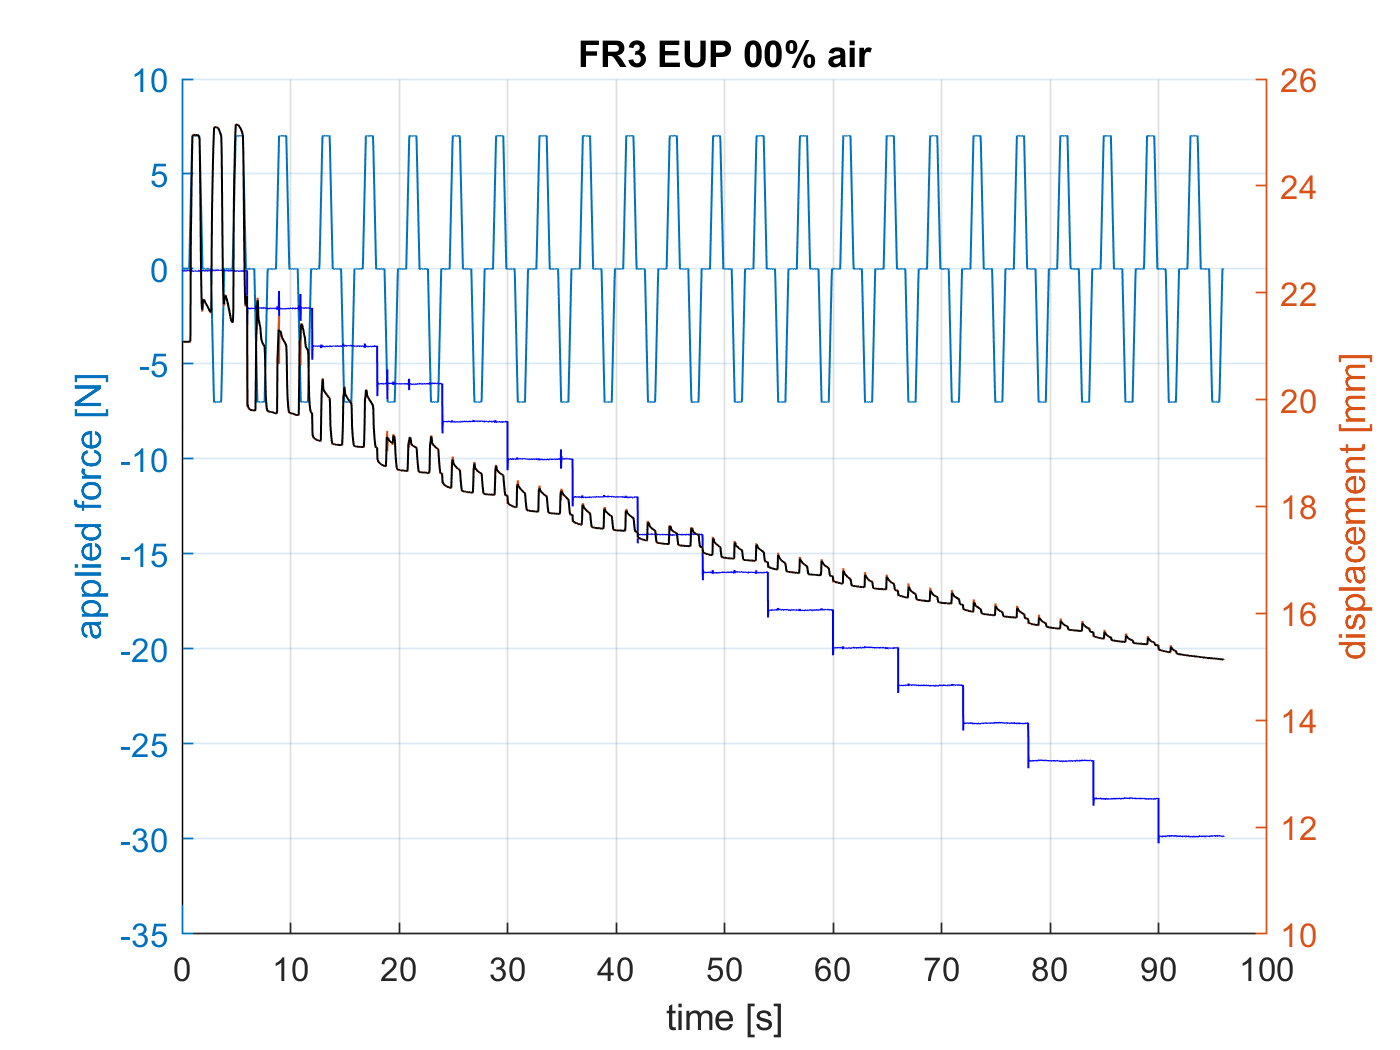

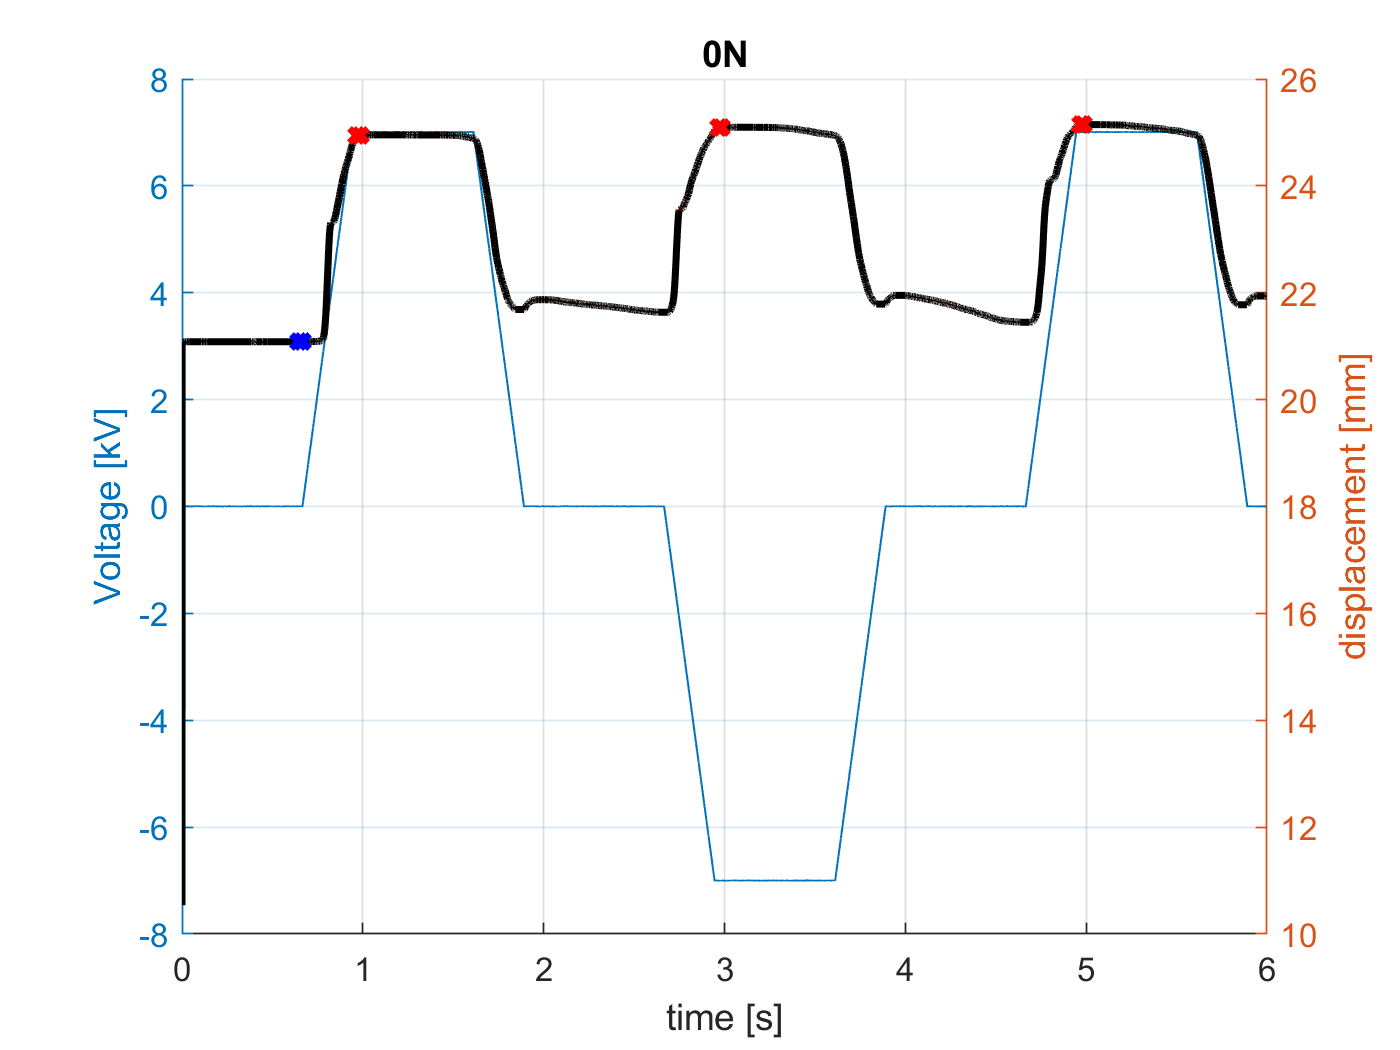

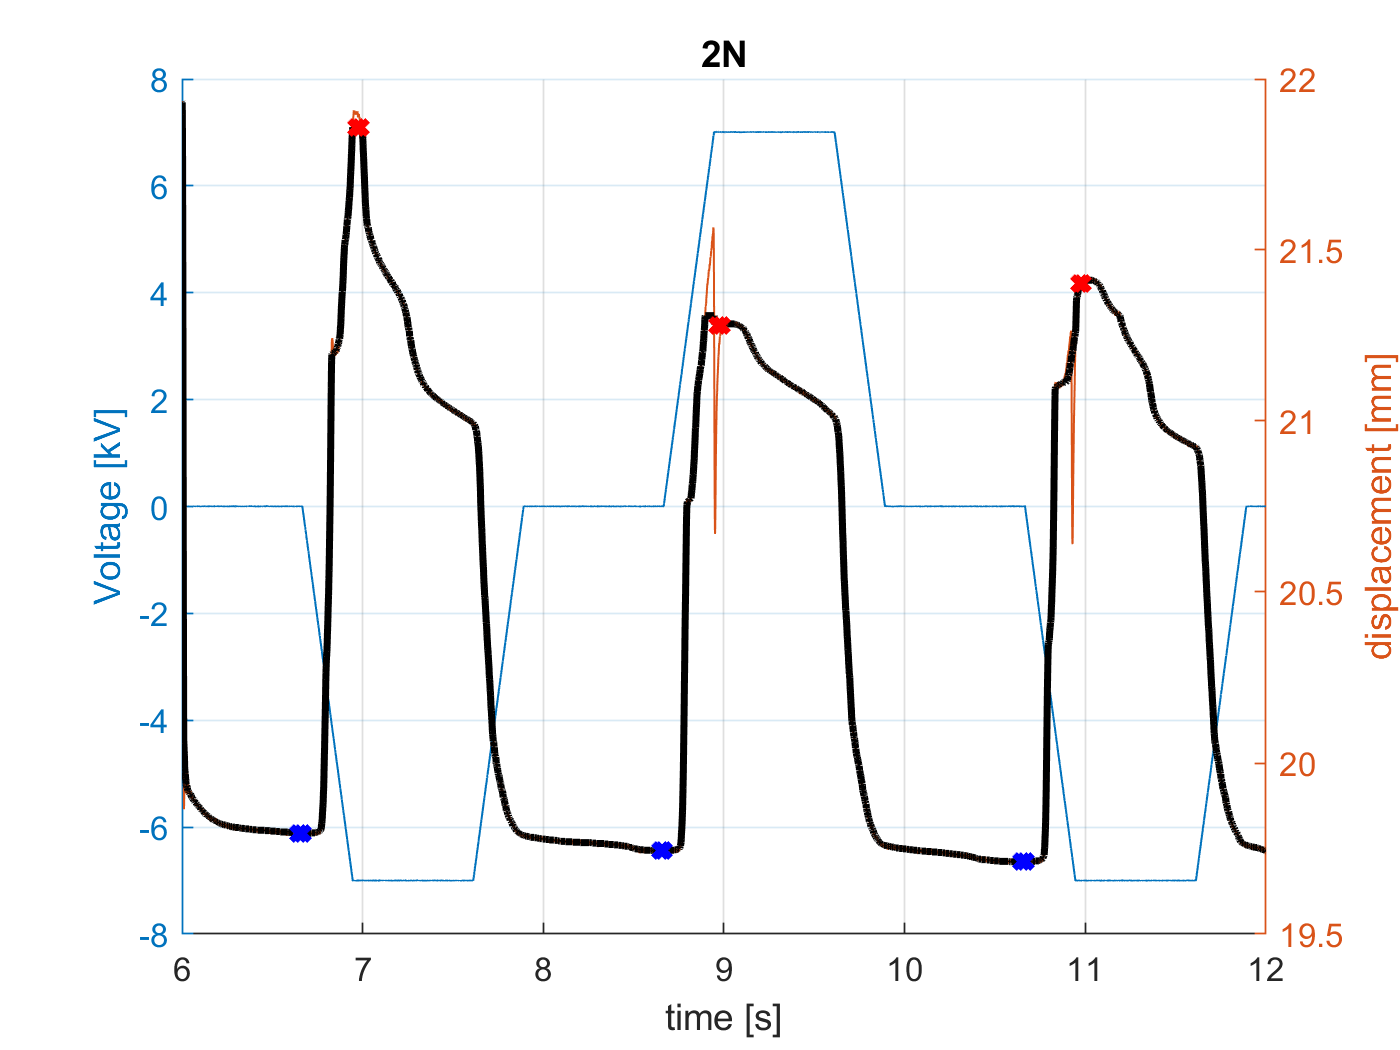

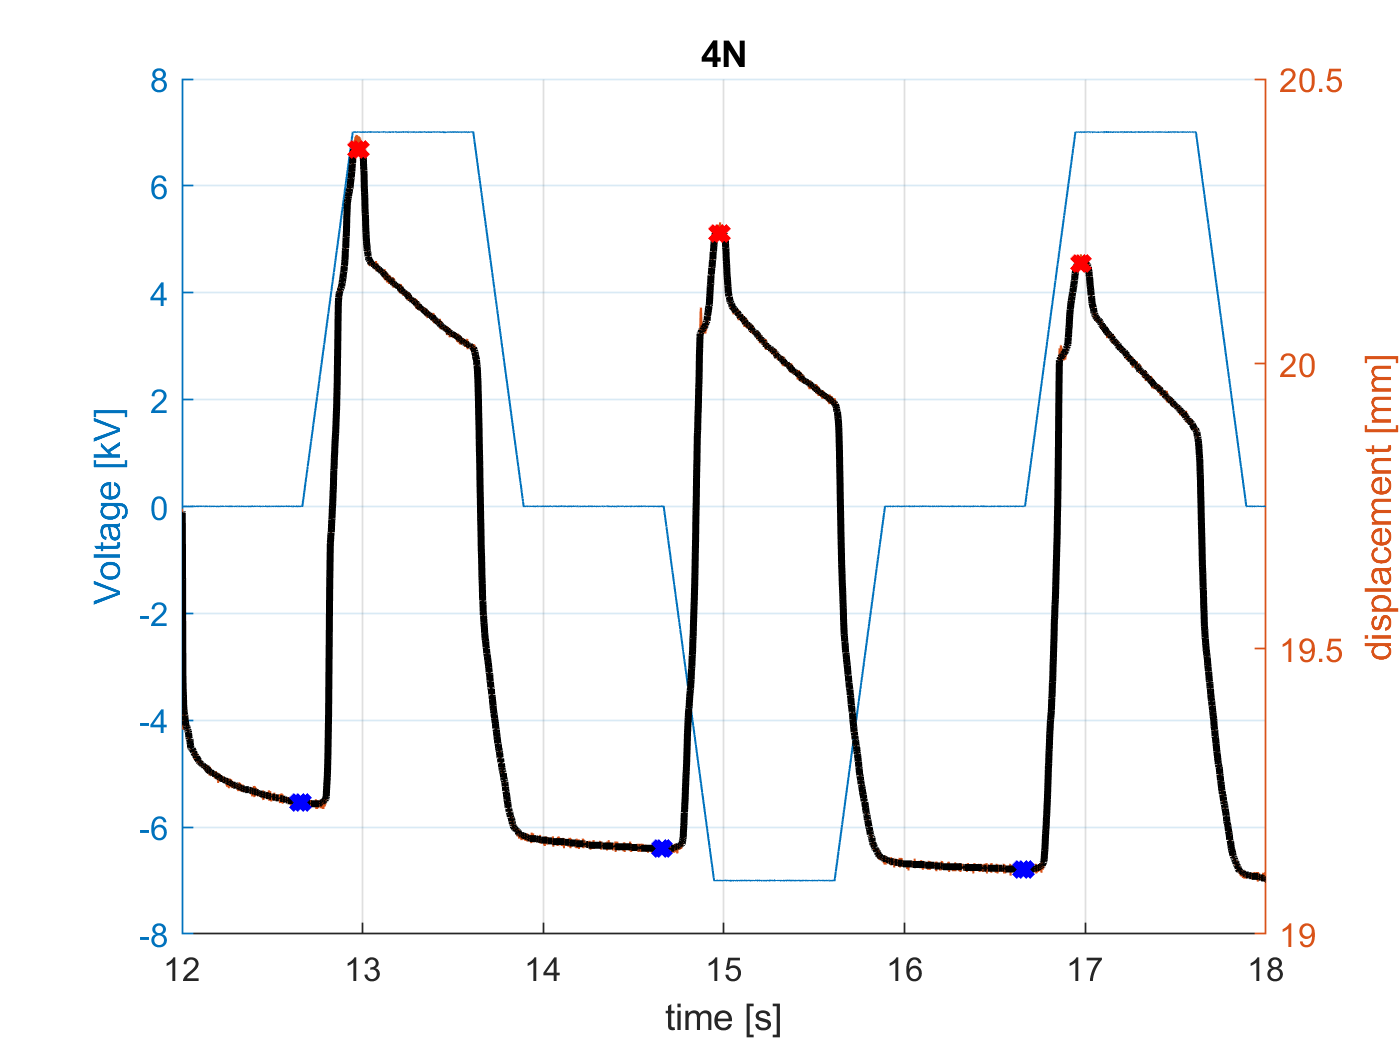

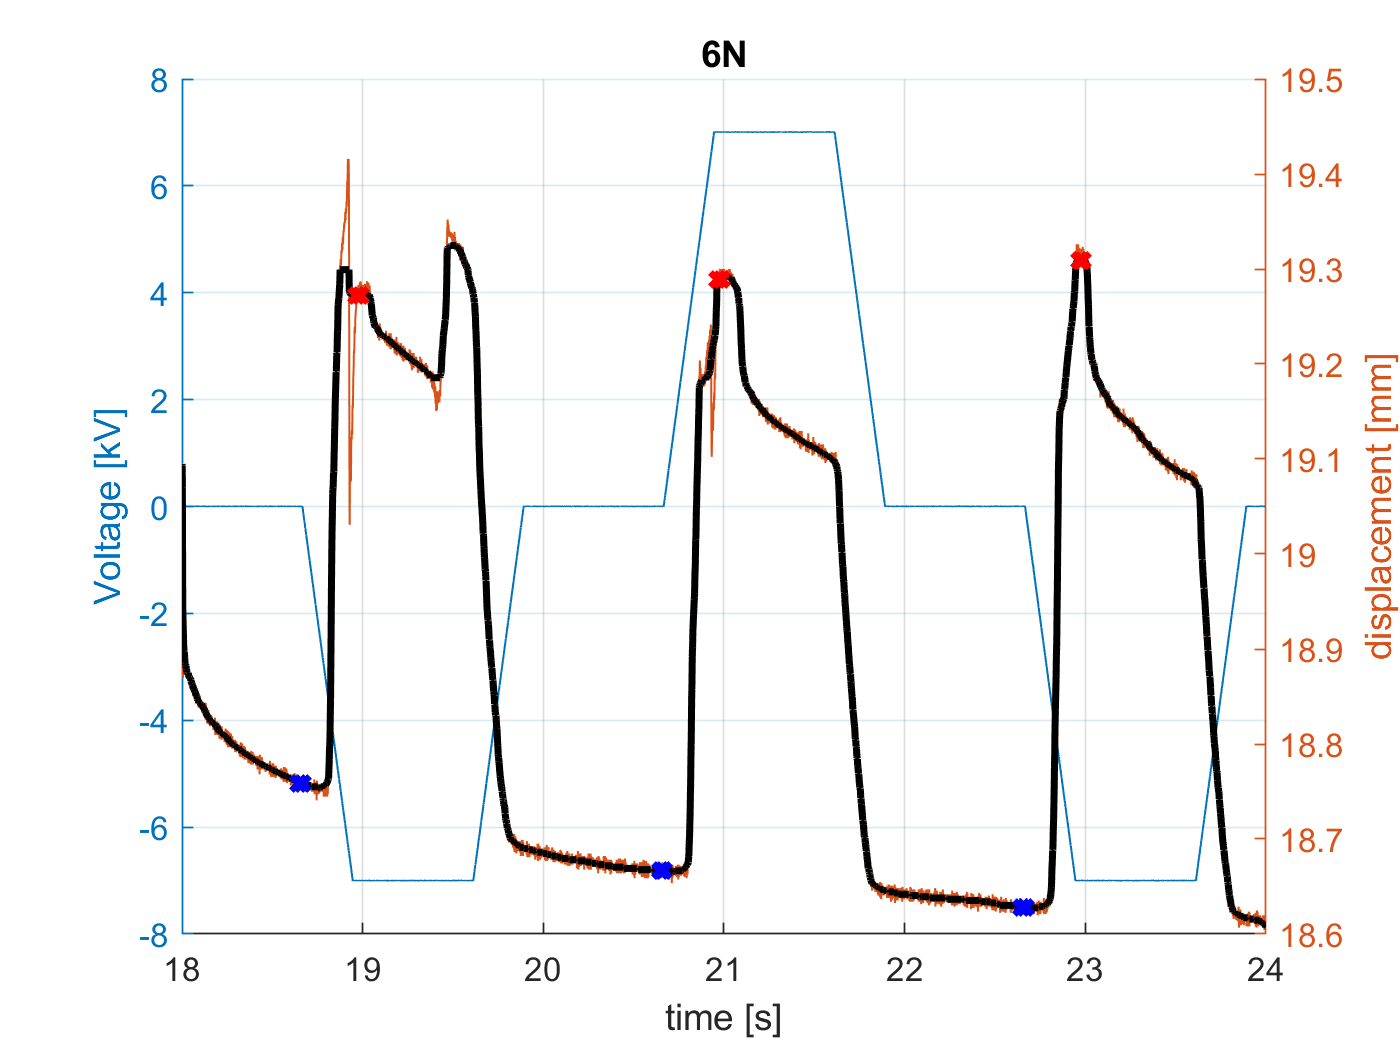

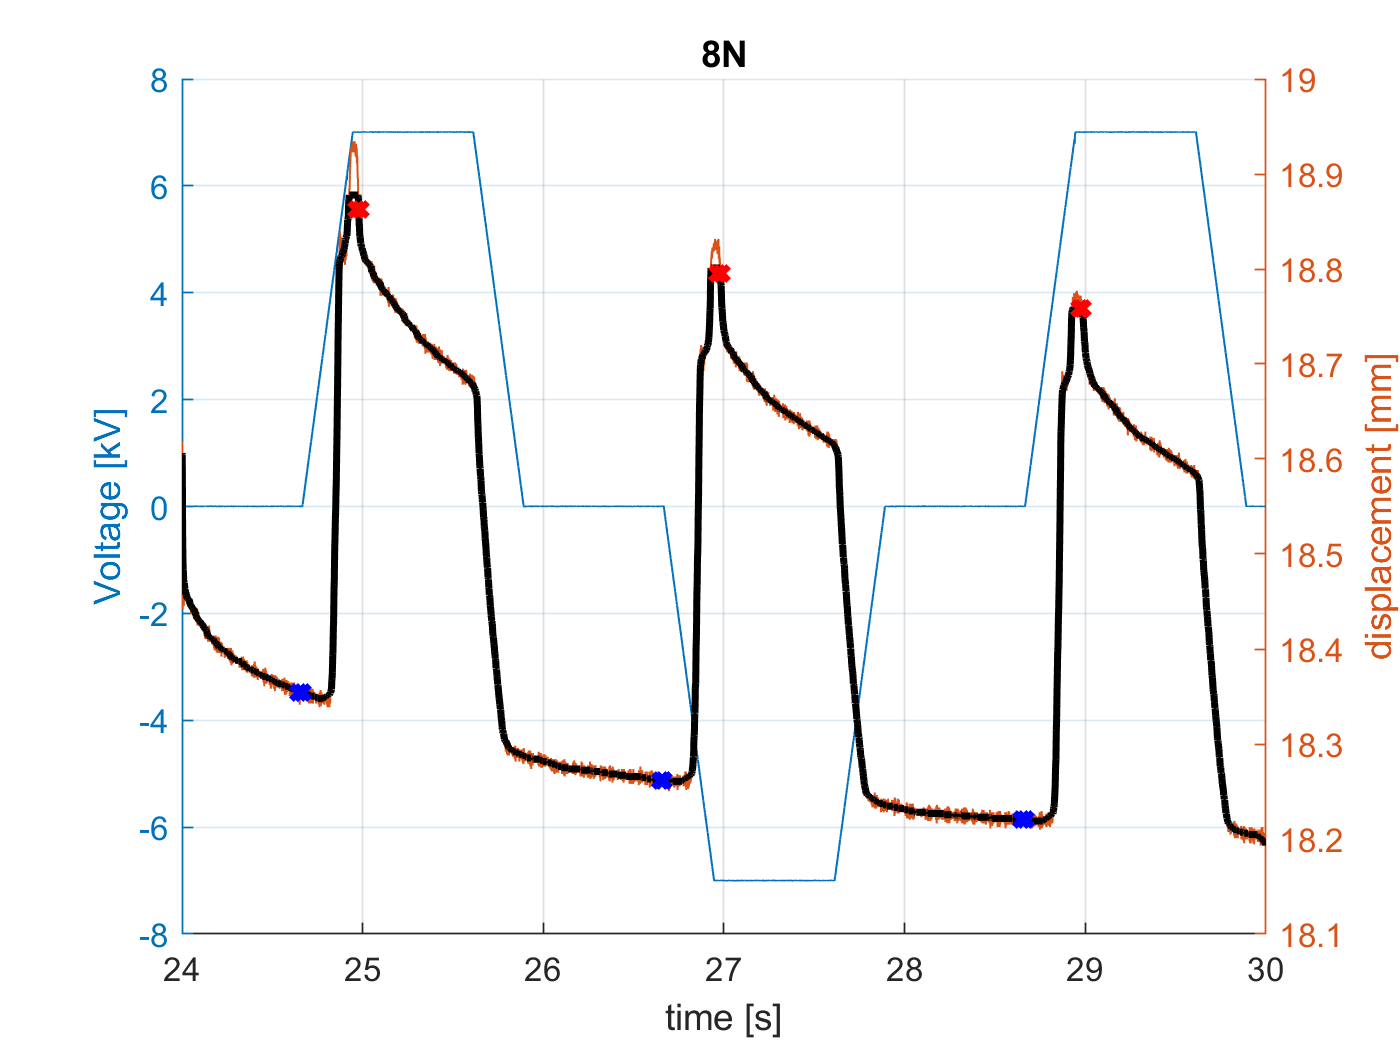

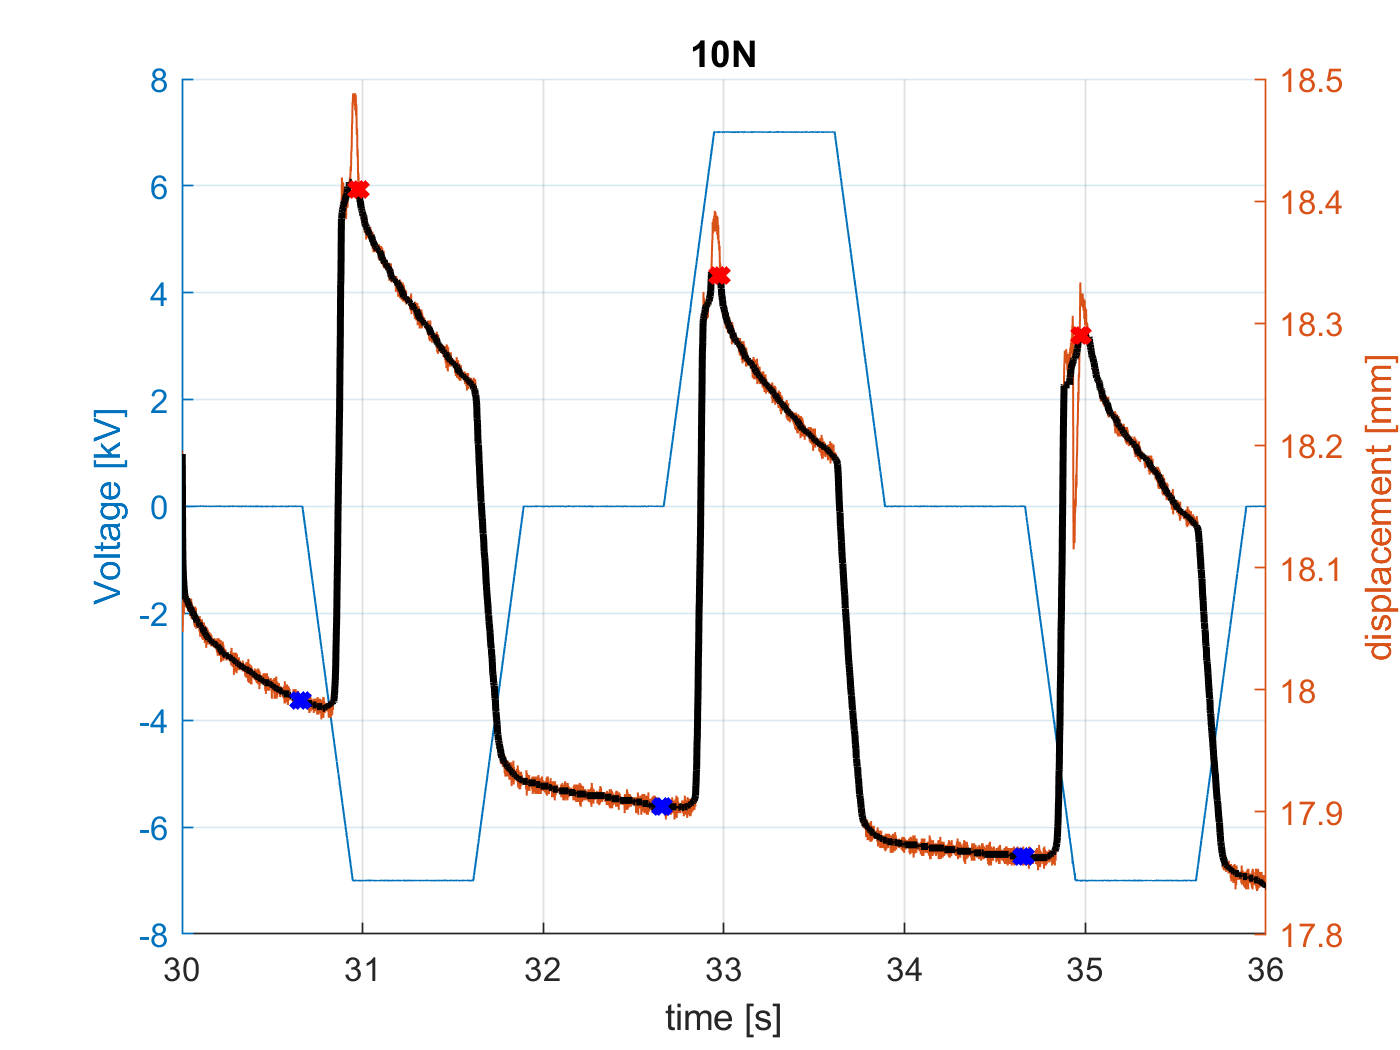

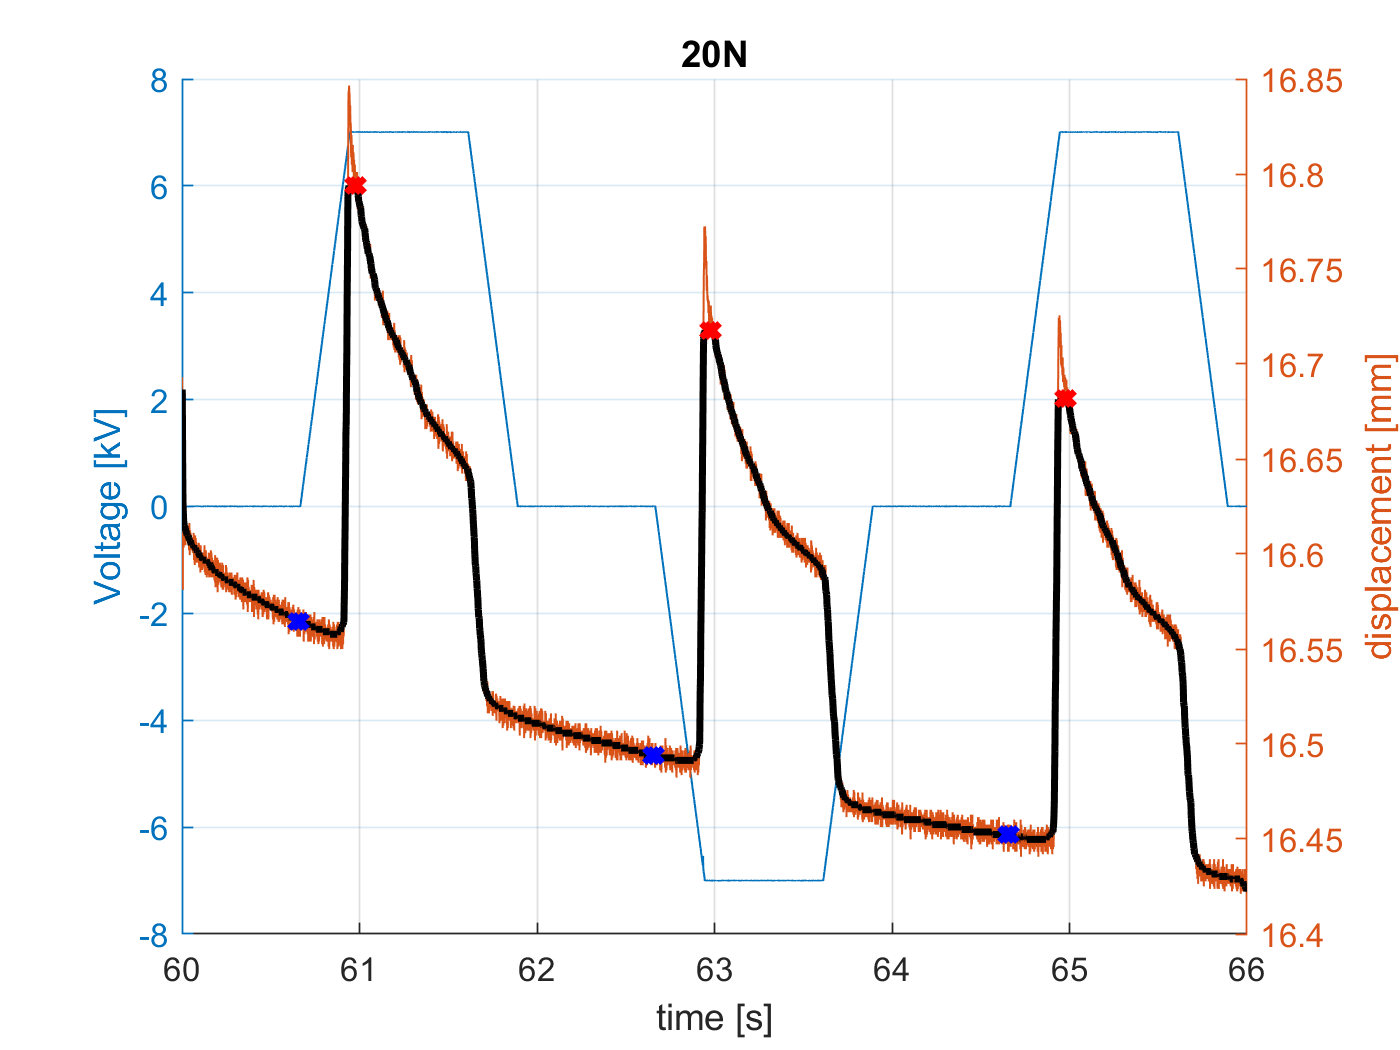

fName = '20x60_EUP_FRB_00_05Hz_7kV_Rampedsquare_25kVs.txt'

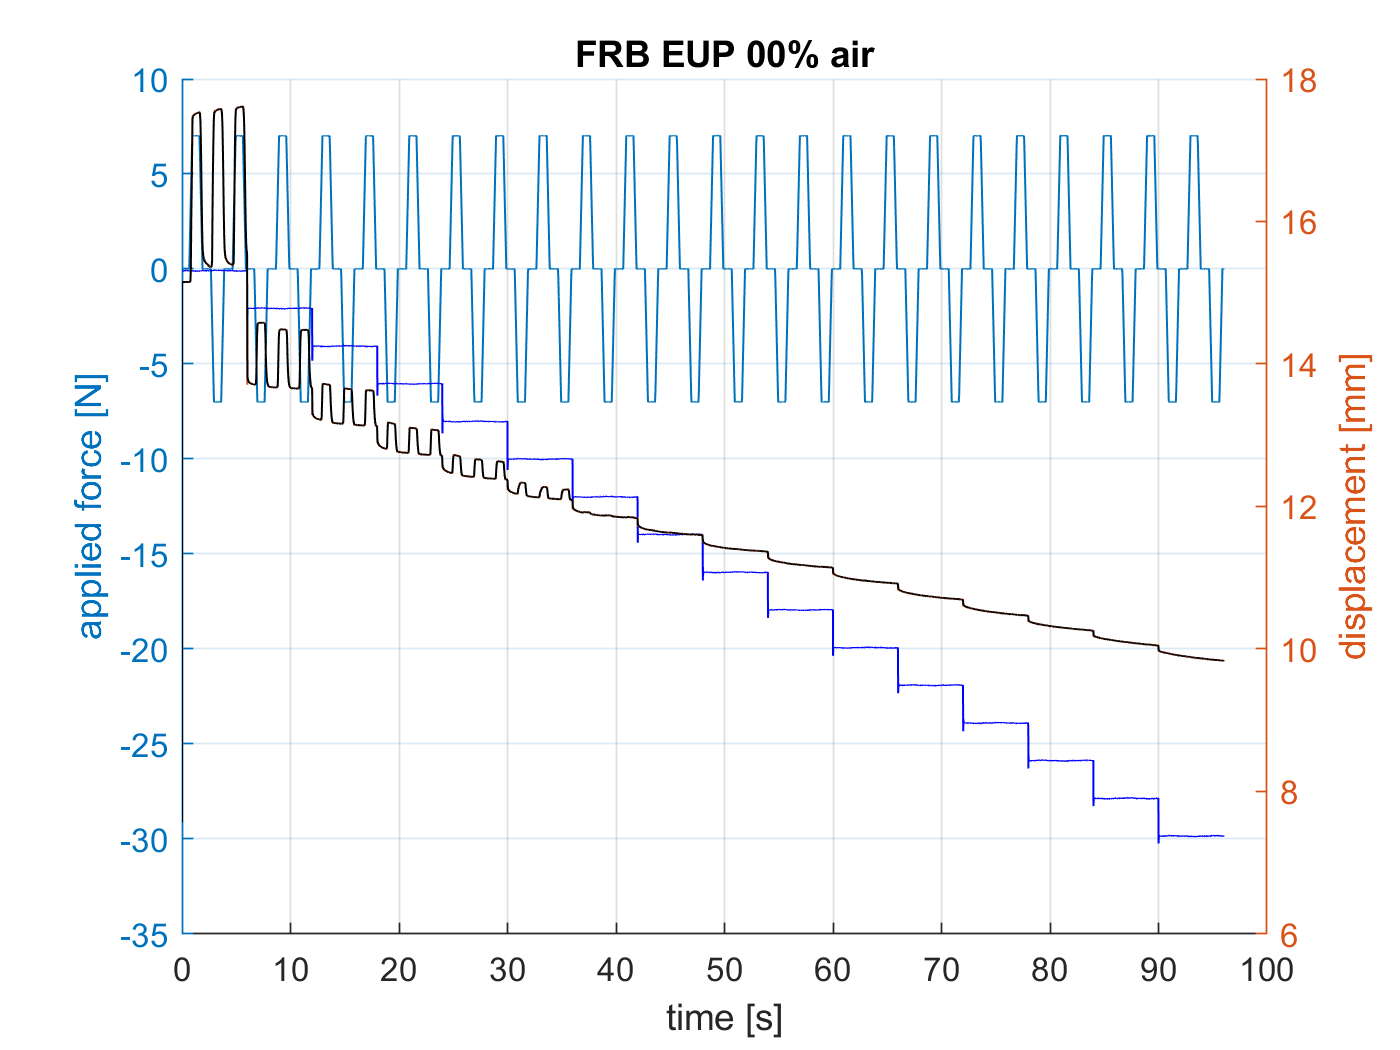

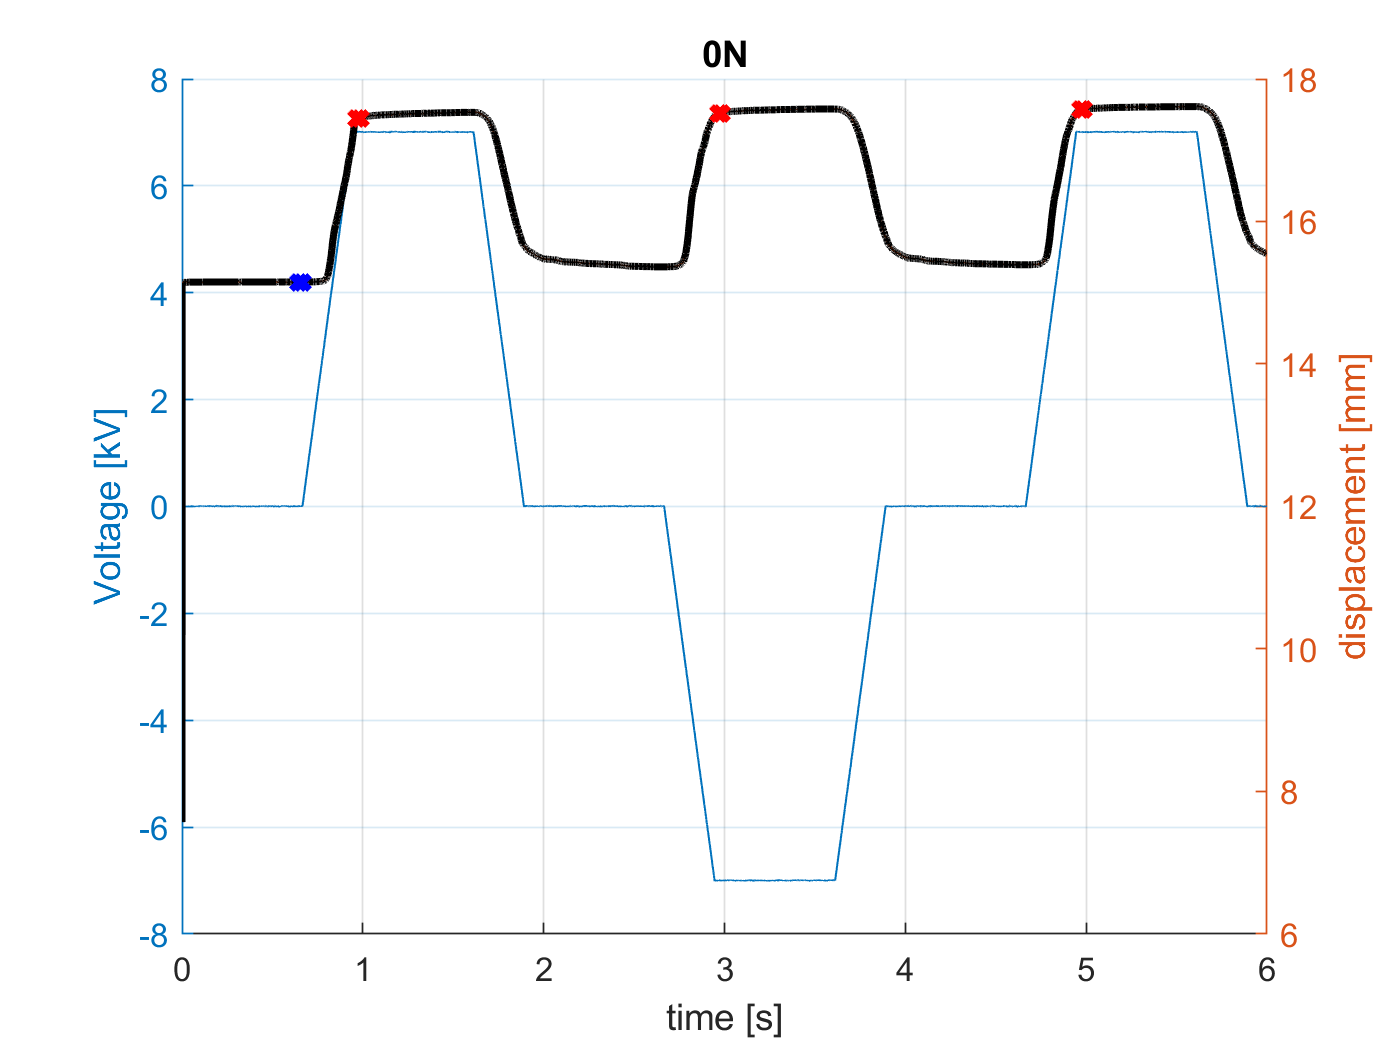

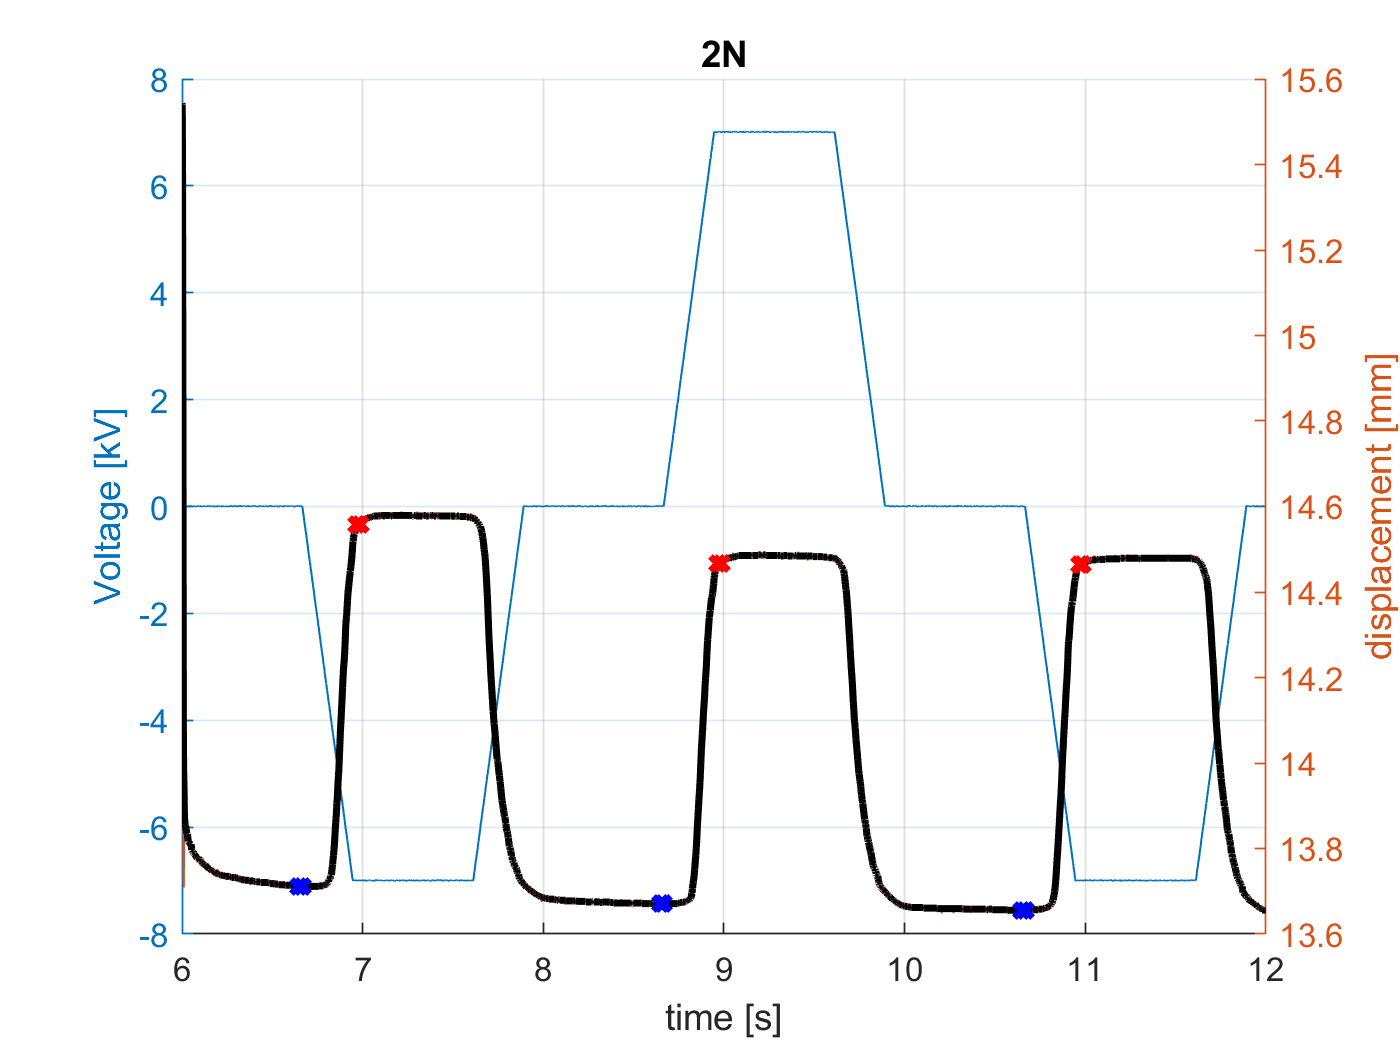

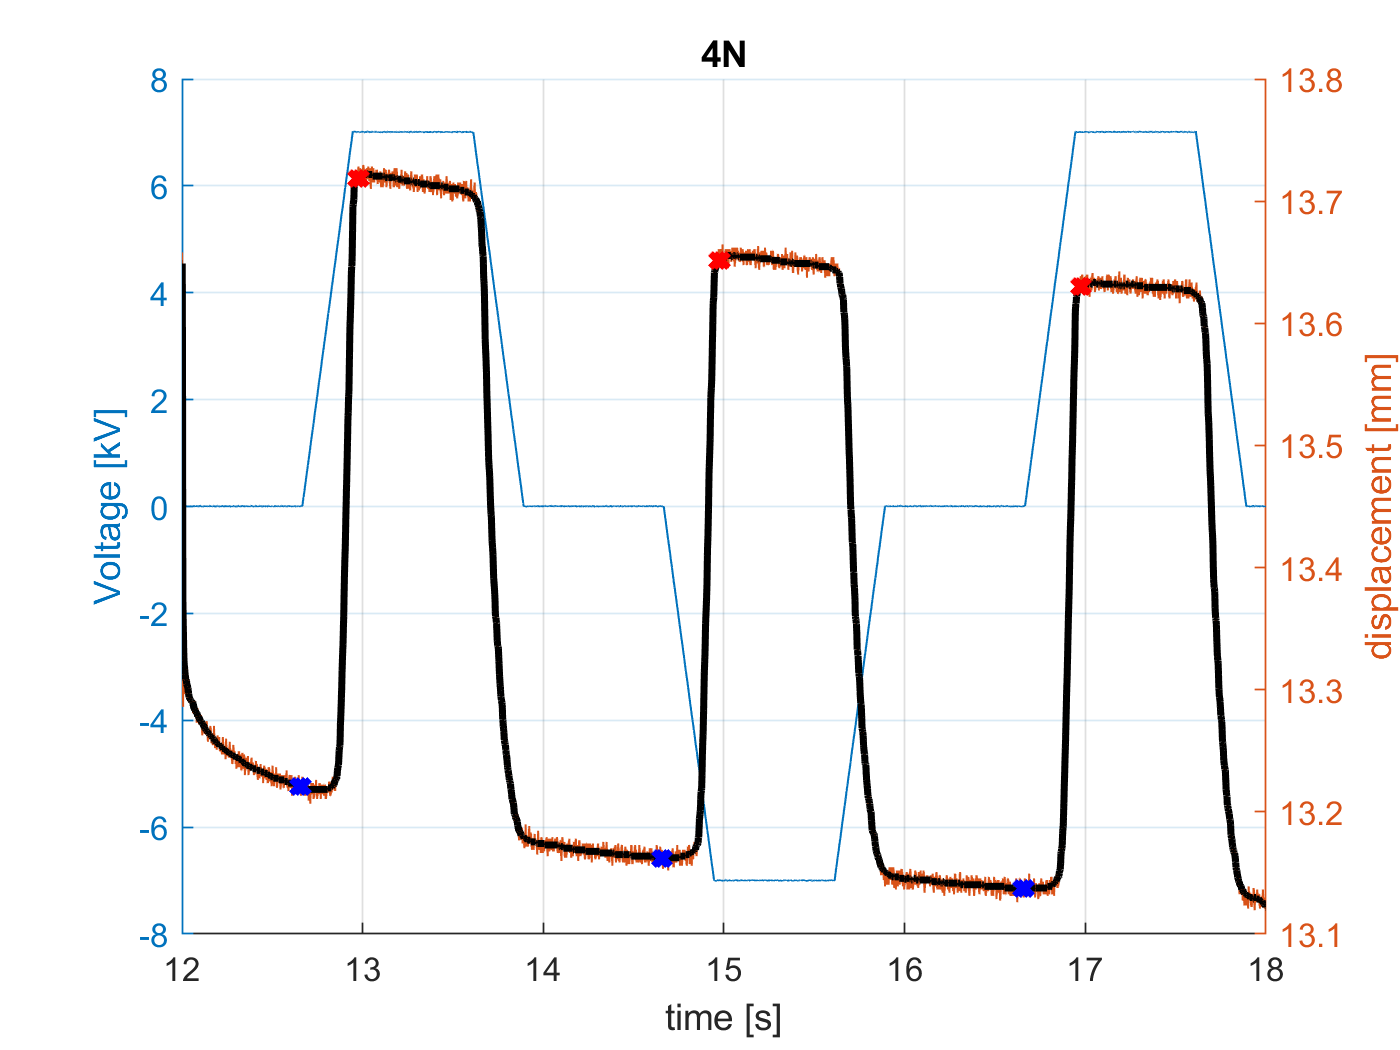

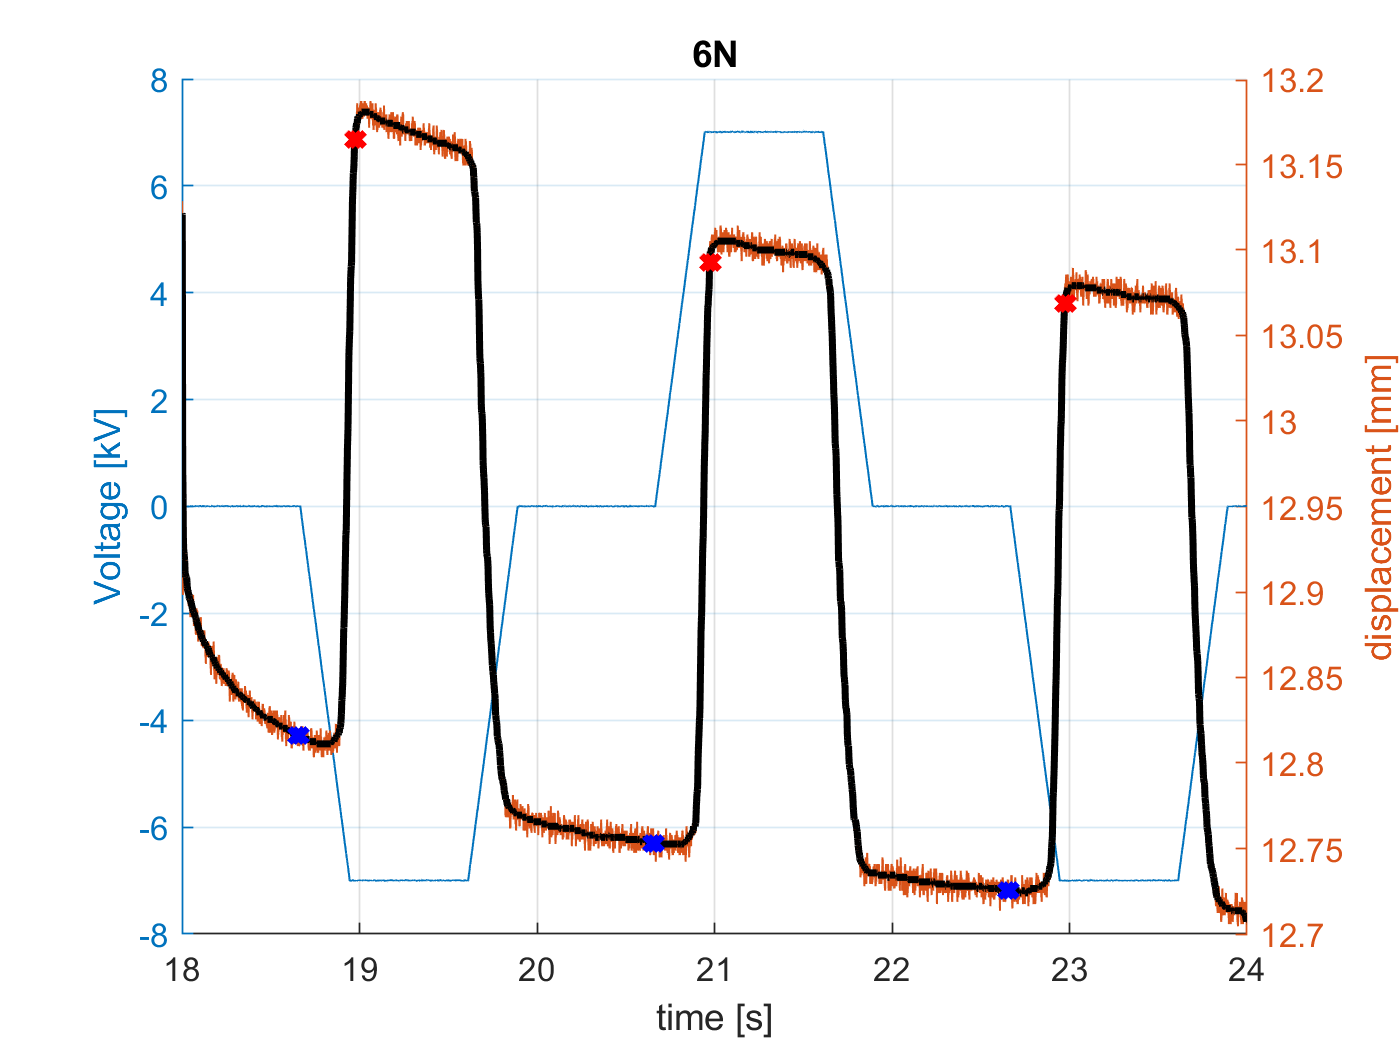

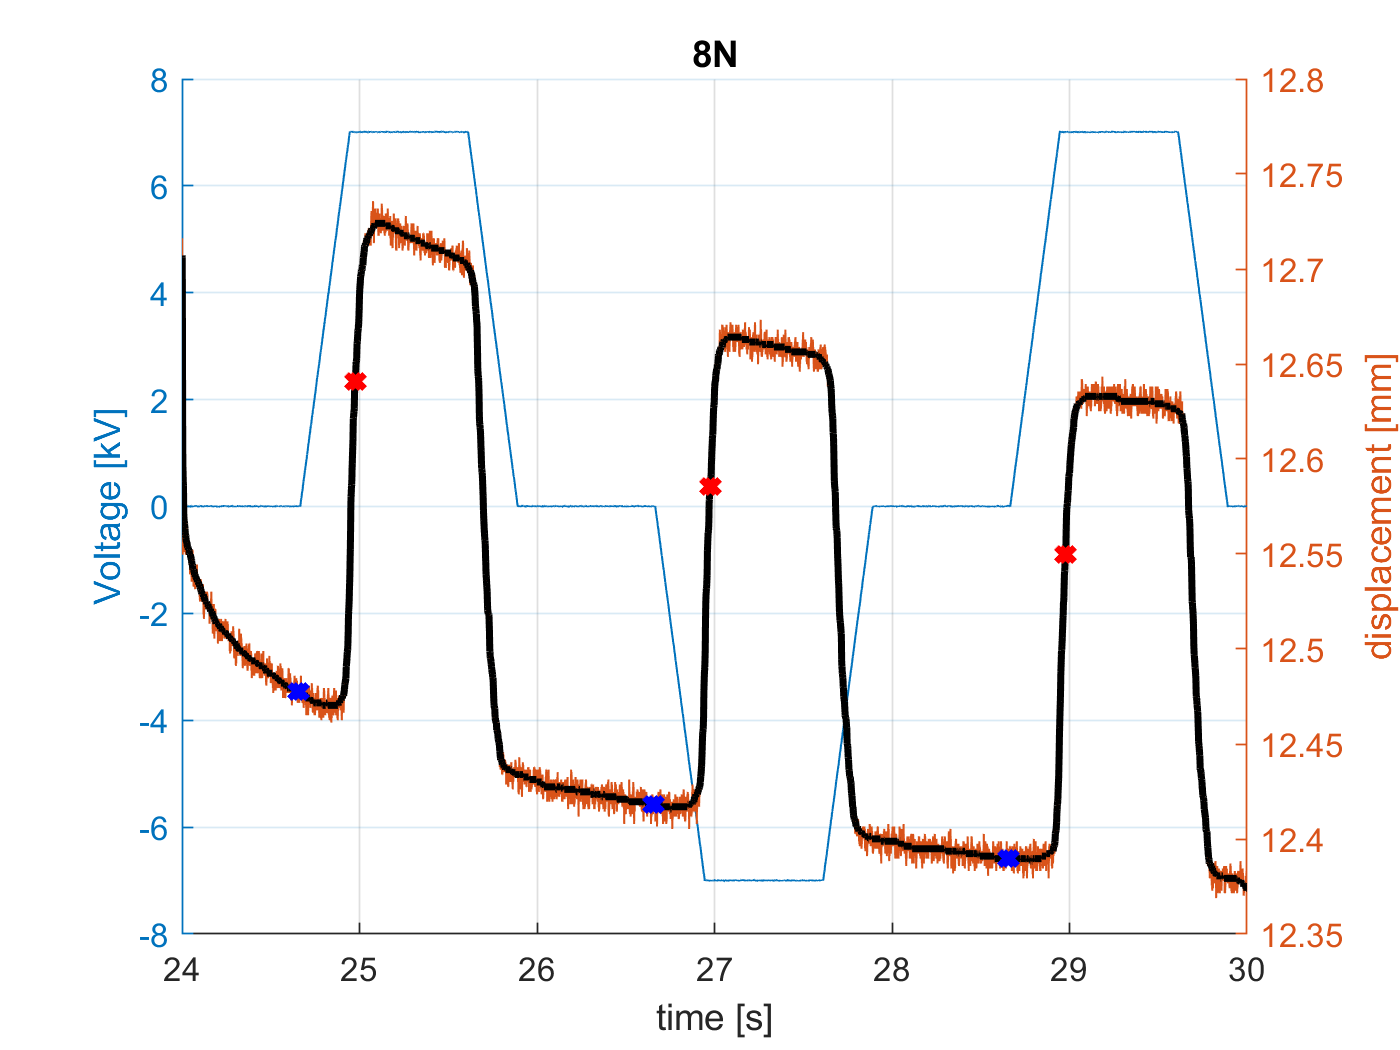

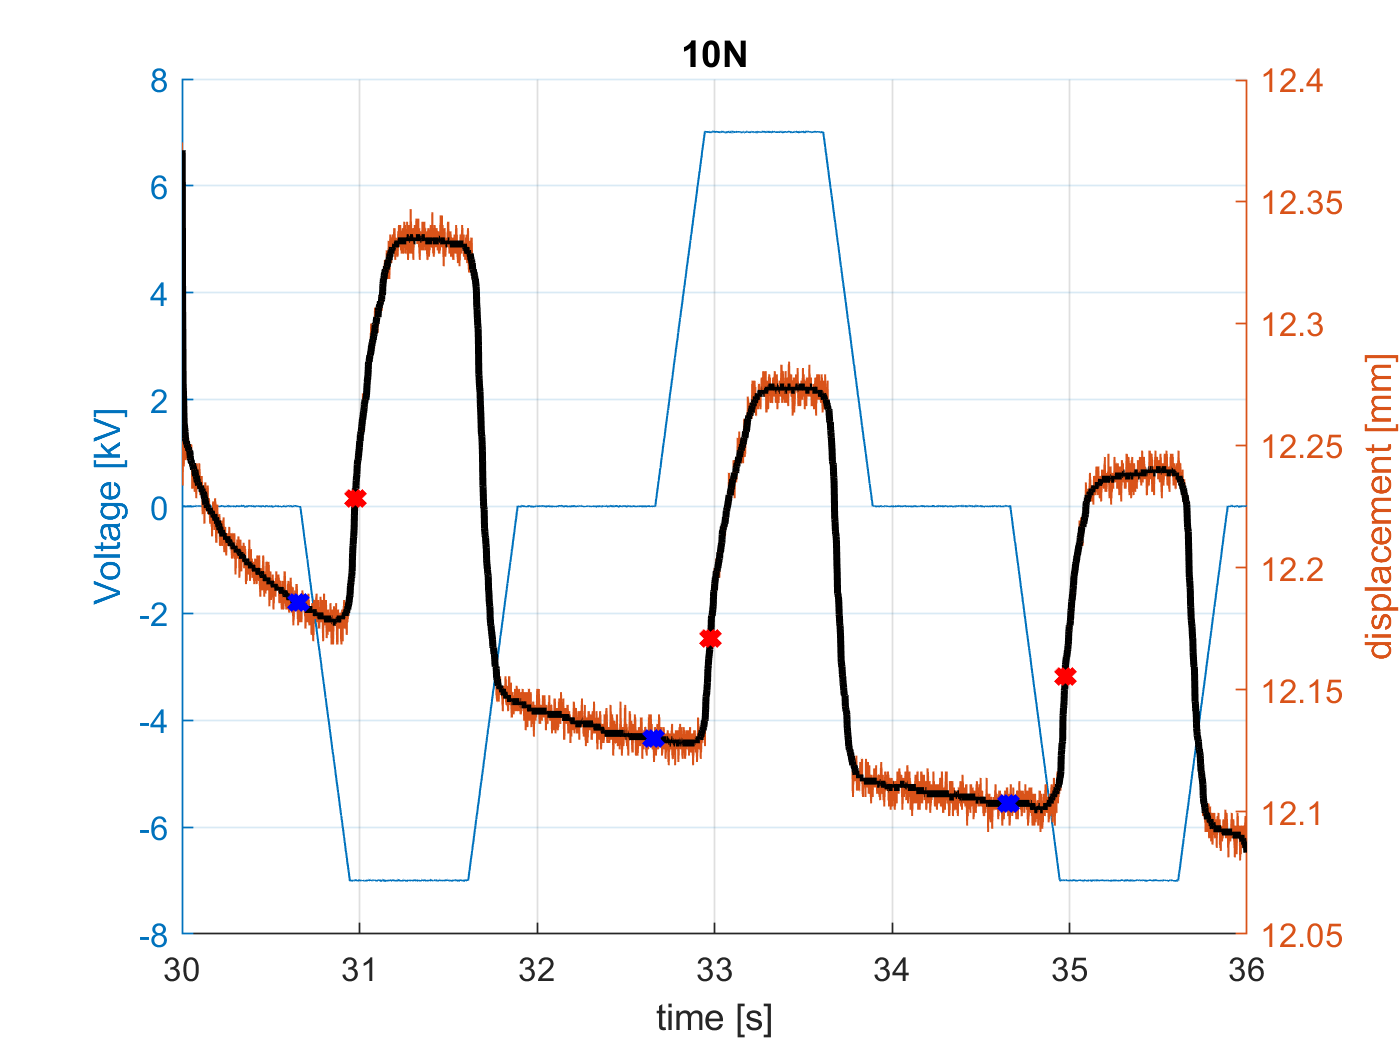

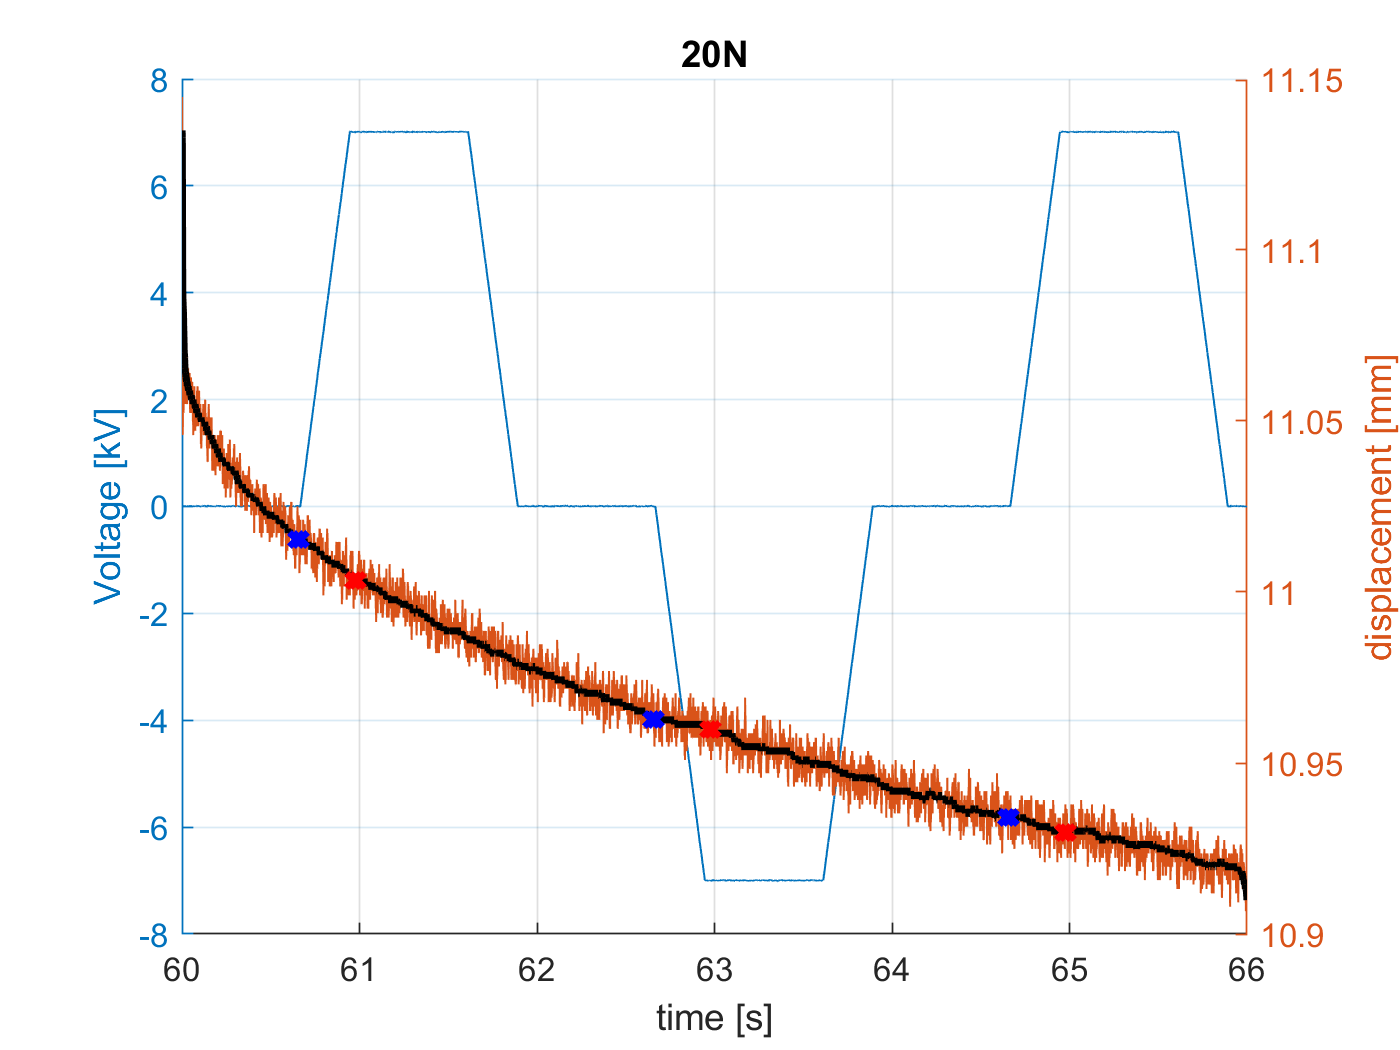

fName = '20x60_EUP_SIL_00_05Hz_7kV_Rampedsquare_25kVs.txt'

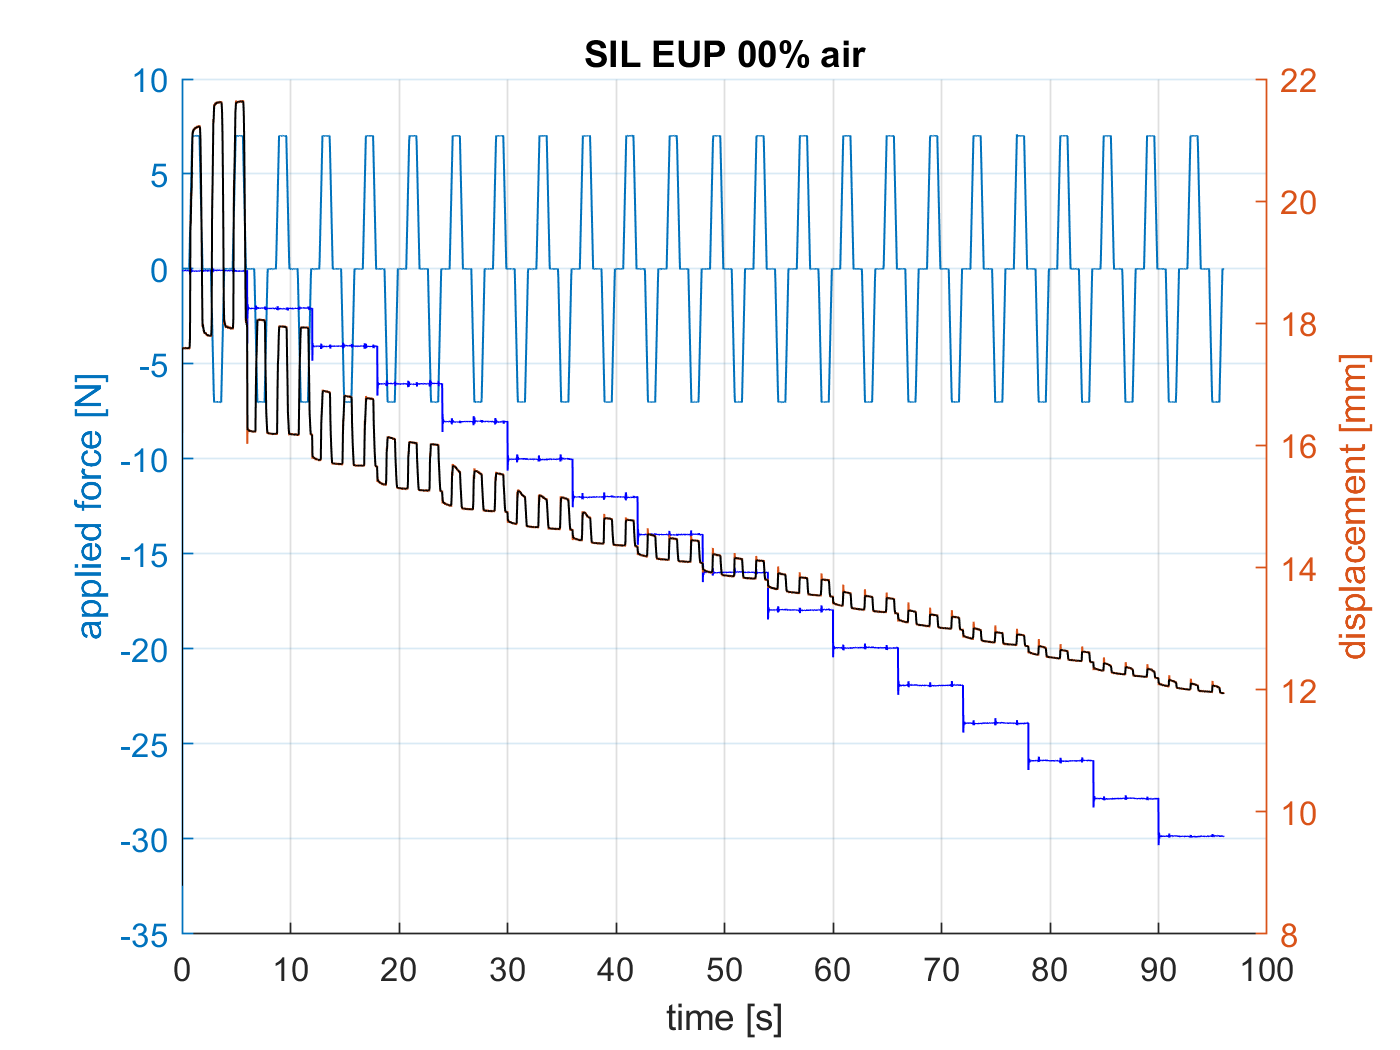

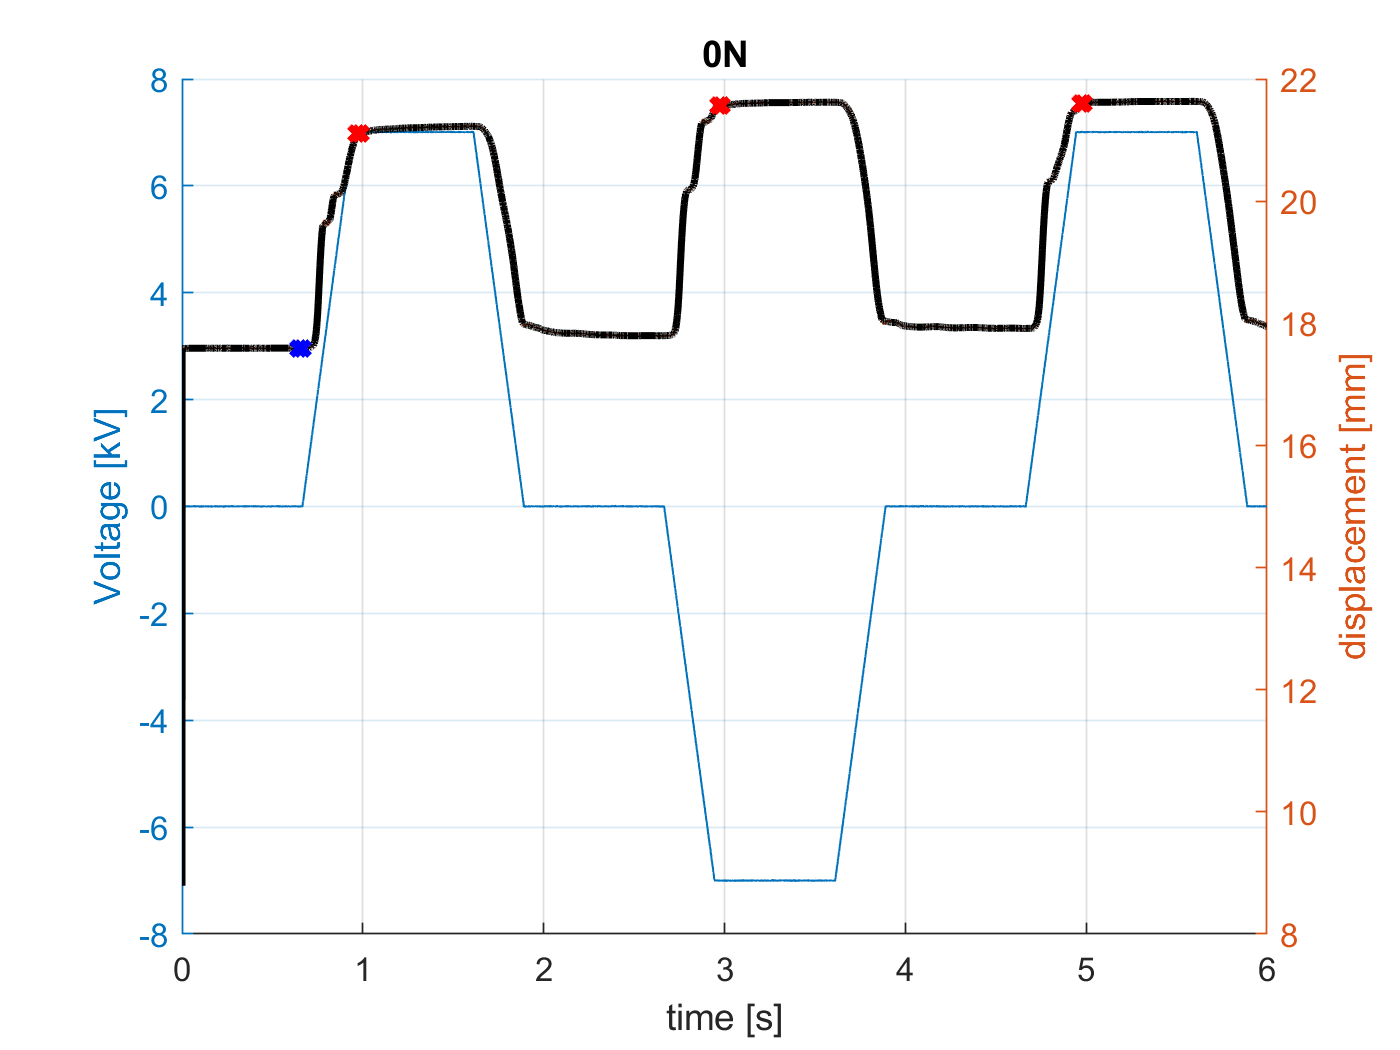

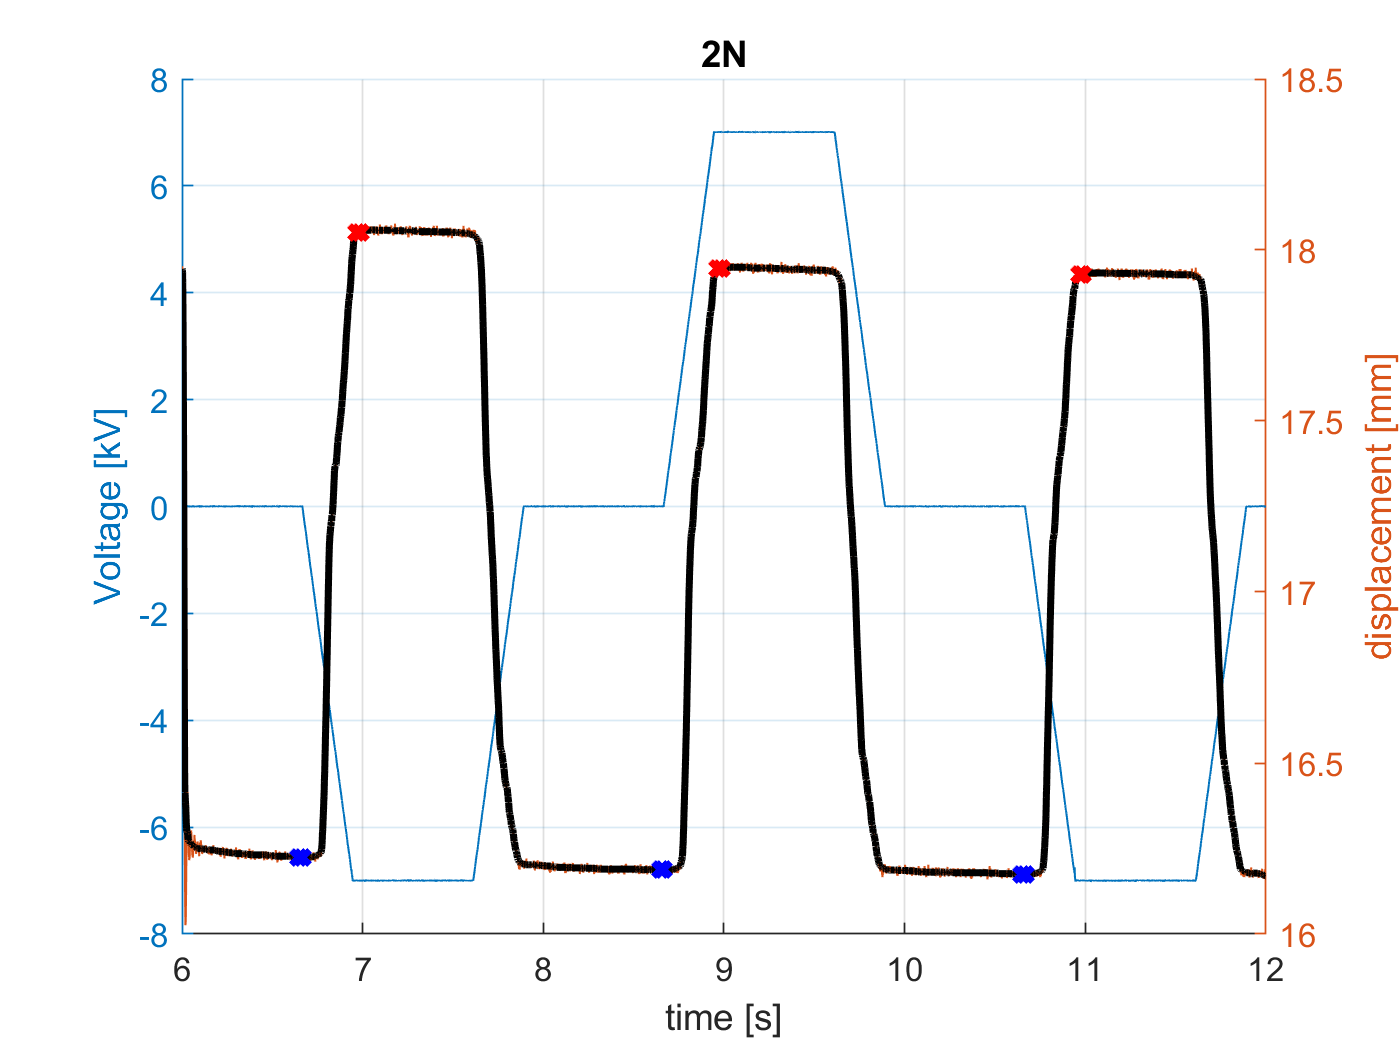

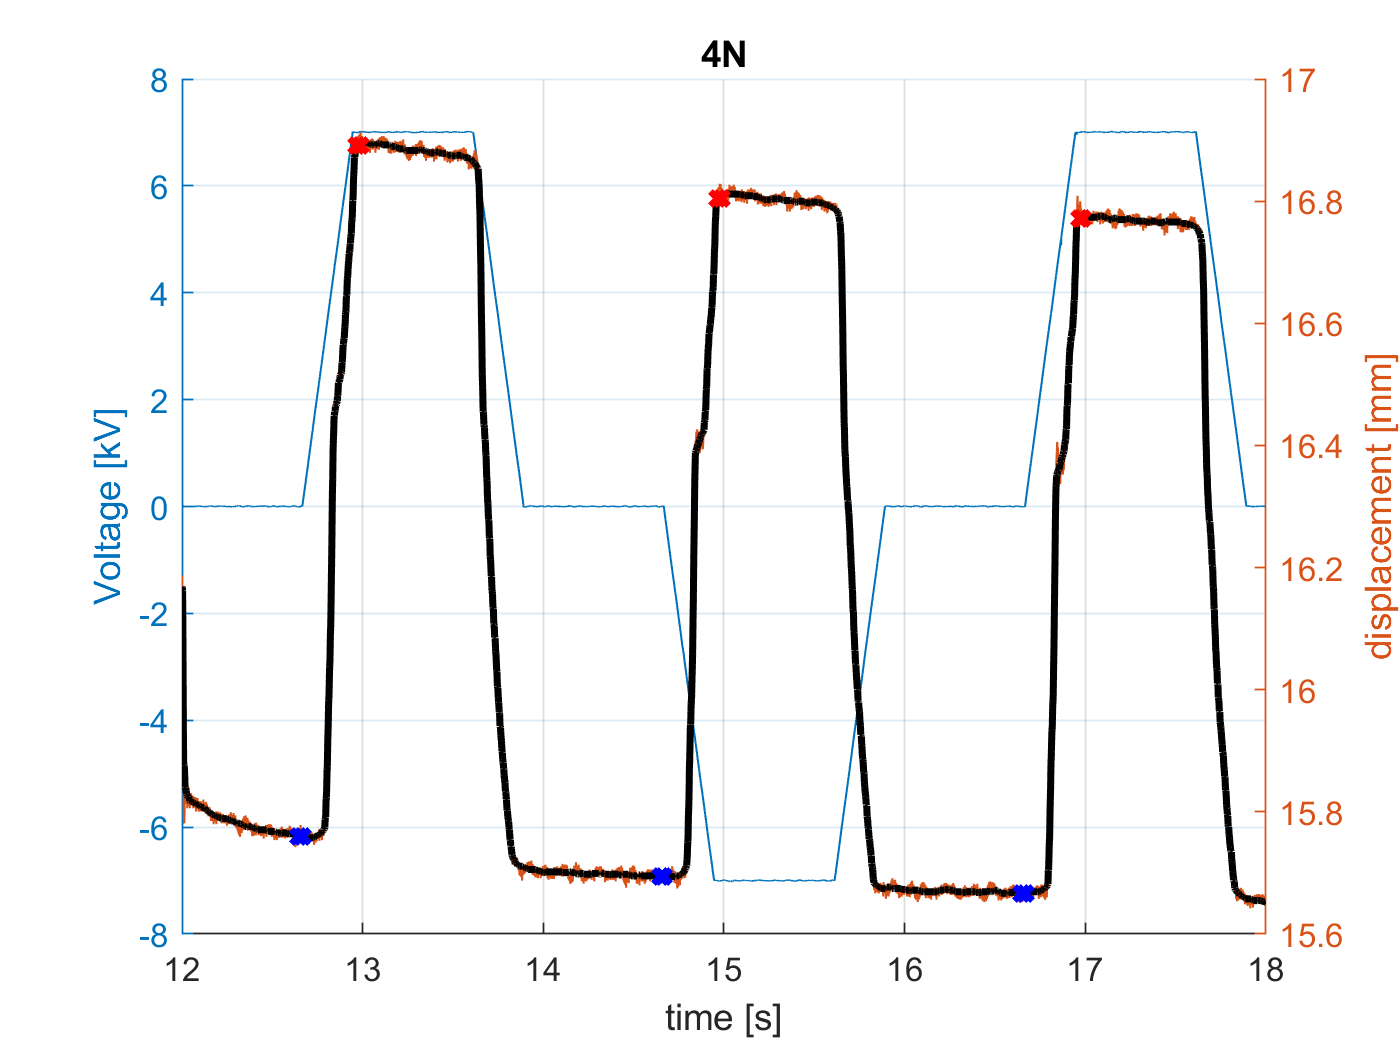

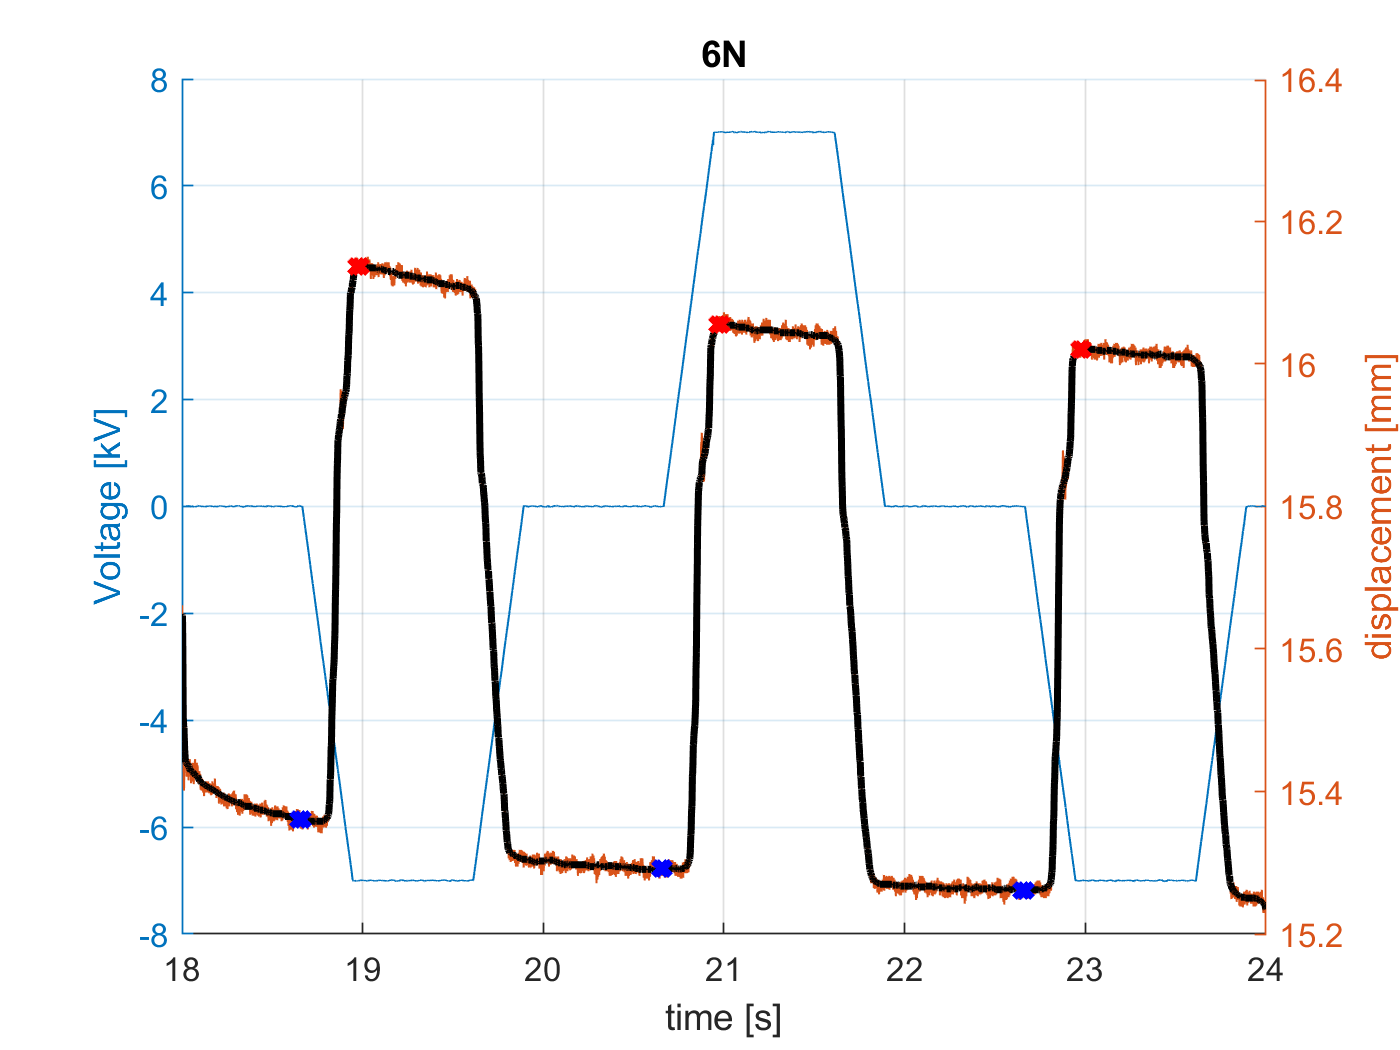

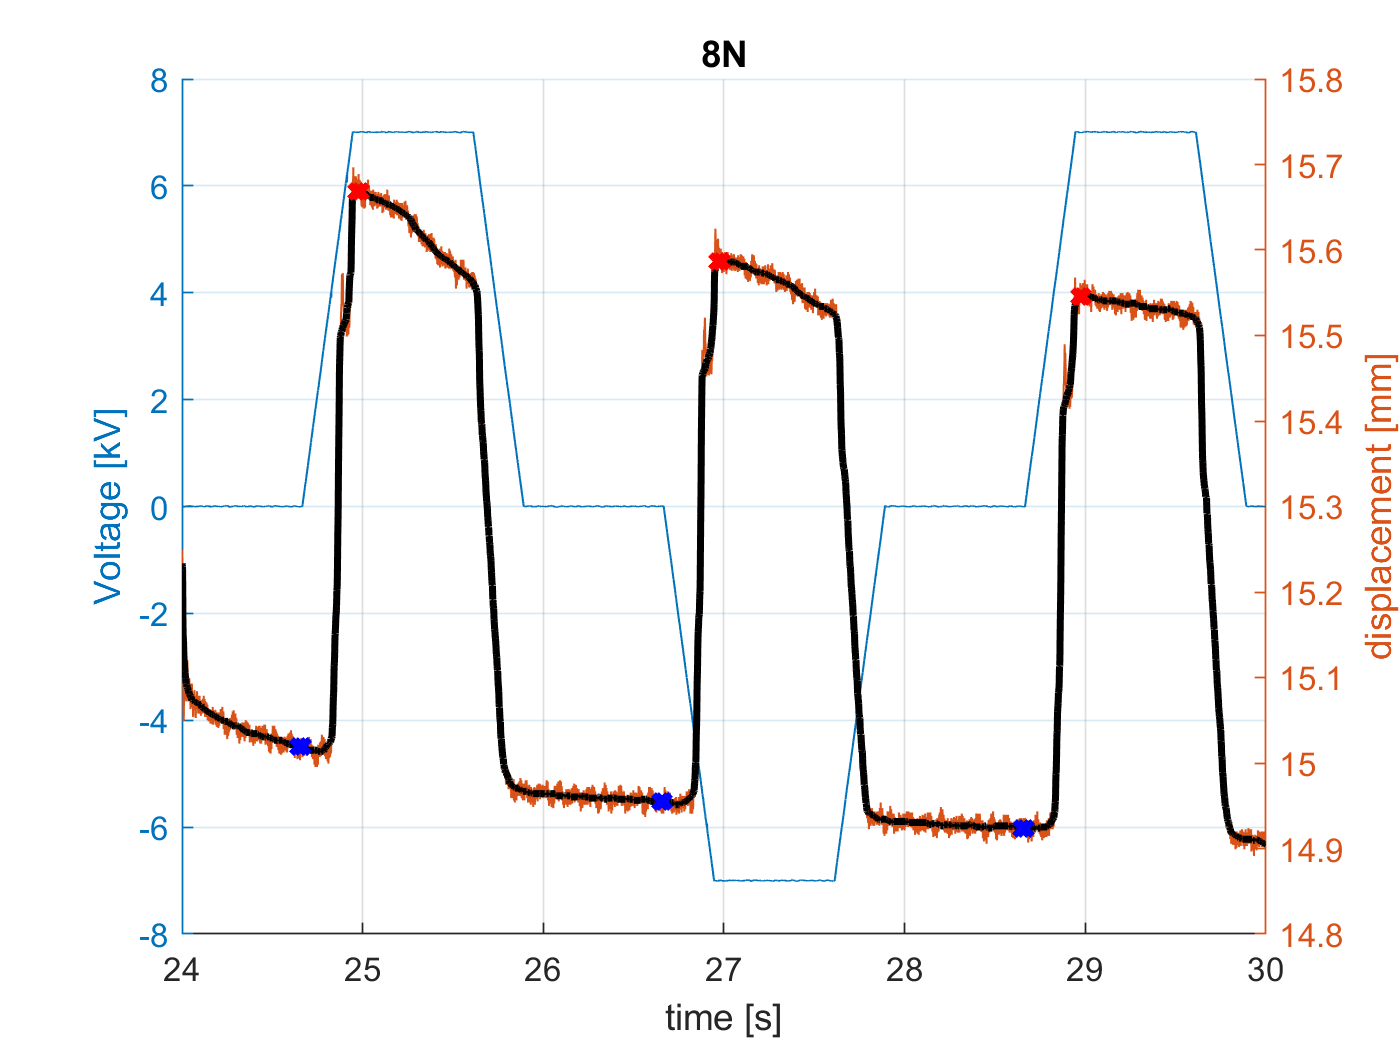

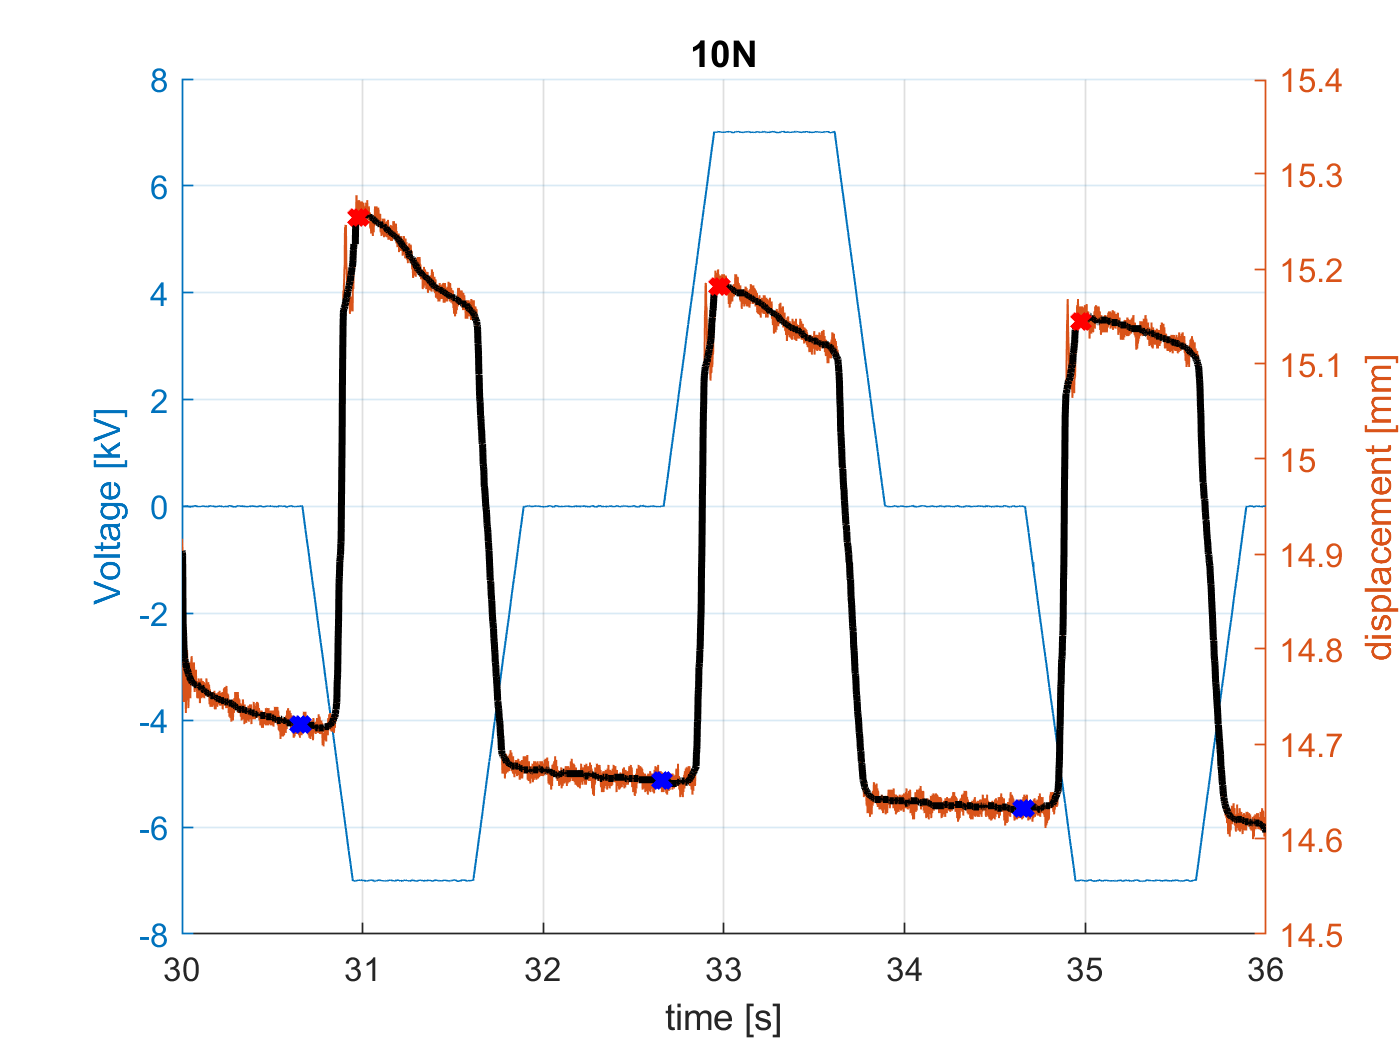

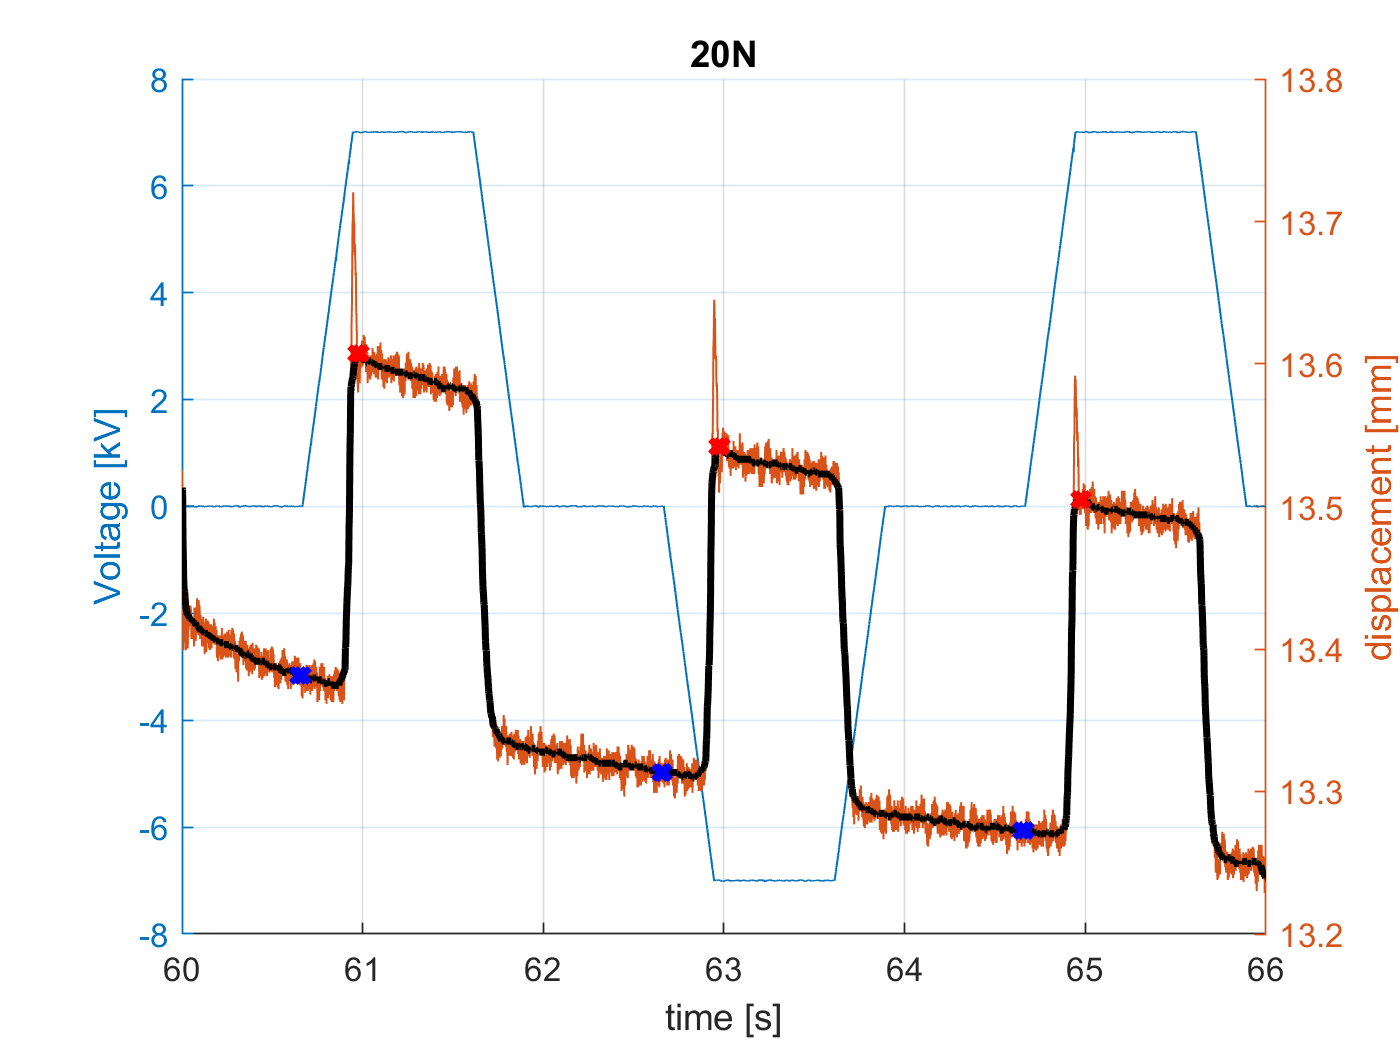


TargetForce = [0, 2, 4, 6, 8, 10, 20, 30];


smoothingFactor = exPara.sampleFreq/10;
numForceSteps = exPara.forceMax/exPara.forceStep + 1;

Data(1: length(FName), 1: numForceSteps) =...
    struct('strain_raw', zeros(exPara.inputRepeat, 1), 'strain', 0, 'force', 0);
for i = 1: length(FName)
    %     keyboard
    fName = FName(i).name
    %     if strcmp(fName, '20x60_EUP_SIL_85_05Hz_7kV_Stepinput.txt')
    %         continue
    %     end
    if contains(fName, 'Step')
        exPara.rampTime = exPara.rampTime_step;
    elseif contains(fName, 'Ramp')
        exPara.rampTime = exPara.rampTime_ramp;
    end
    [Time, Volt, Force, Disp, Trigger] = importfile_strainRaw(['raw_', fName]);
    %     [SF_strain, SF_force] = importfile_strain(fName);
    Disp = -Disp*exPara.kD;
    Force = Force*exPara.kF;
    Volt = correctTimedelay(Volt);
    
    % filter raw data
    Disp_fil = medfilt1(Disp, smoothingFactor);
    Force_fil = medfilt1(Force, smoothingFactor);
    
    % plot overall
    figure(100*i)
    clf
    hold on
    
    yyaxis('left')
    plot(Time, Volt)
    plot(Time, Force, 'b-')
    ylabel('applied force [N]')
    xlabel('time [s]')
    
    yyaxis('right')
    plot(Time, Disp)
    plot(Time, Disp_fil, 'k-')
    %     ylim([-0.5, 1.5])
    ylabel('displacement [mm]')
    grid on
    
    
    % calculate strain
    
    
    for j = 1: numForceSteps
        Data(i, j) = detectStrain_cnv(Time, Force_fil, Disp_fil, (j-1)*exPara.forceStep, exPara, 0);
    end
    
    
    
    title([fName(11:13), ' ', fName(7:9), ' ', fName(15:16), '% air'])
    for j = 1: numel(TargetForce)
        targetForce = TargetForce(j);
        idx0 = fix(targetForce/exPara.forceStep*1/exPara.inputFreq*exPara.inputRepeat*exPara.sampleFreq) + 1;
        idx1 = idx0 - 1 + fix(1/exPara.inputFreq*exPara.inputRepeat*exPara.sampleFreq);
        
        figure(100*i+j)
        clf
        hold on
        
        yyaxis('left')
        plot(Time(idx0:idx1), Volt(idx0:idx1))
        %     plot(Time, RefFreq)
        ylabel('Voltage [kV]')
        xlabel('time [s]')
        %     legend('real input', 'ref input for TF', 'output', "Location", "northoutside", "Orientation","horizontal")
        
        yyaxis('right')
        plot(Time(idx0:idx1), Disp(idx0:idx1))
        plot(Time(idx0:idx1), Disp_fil(idx0:idx1), 'k-', 'LineWidth', 2)
        
        %         ylim([-1.0, 1.0])
        ylabel('displacement [mm]')
        grid on
        %         xlim([Time(idx0) - 5/targetFreq, Time(idx0) + 5/targetFreq])
        grid on
        title([num2str(targetForce), 'N'])
        
        detectStrain_cnv(Time, Force_fil, Disp_fil, targetForce, exPara, 1);
        
    end
    
    
end

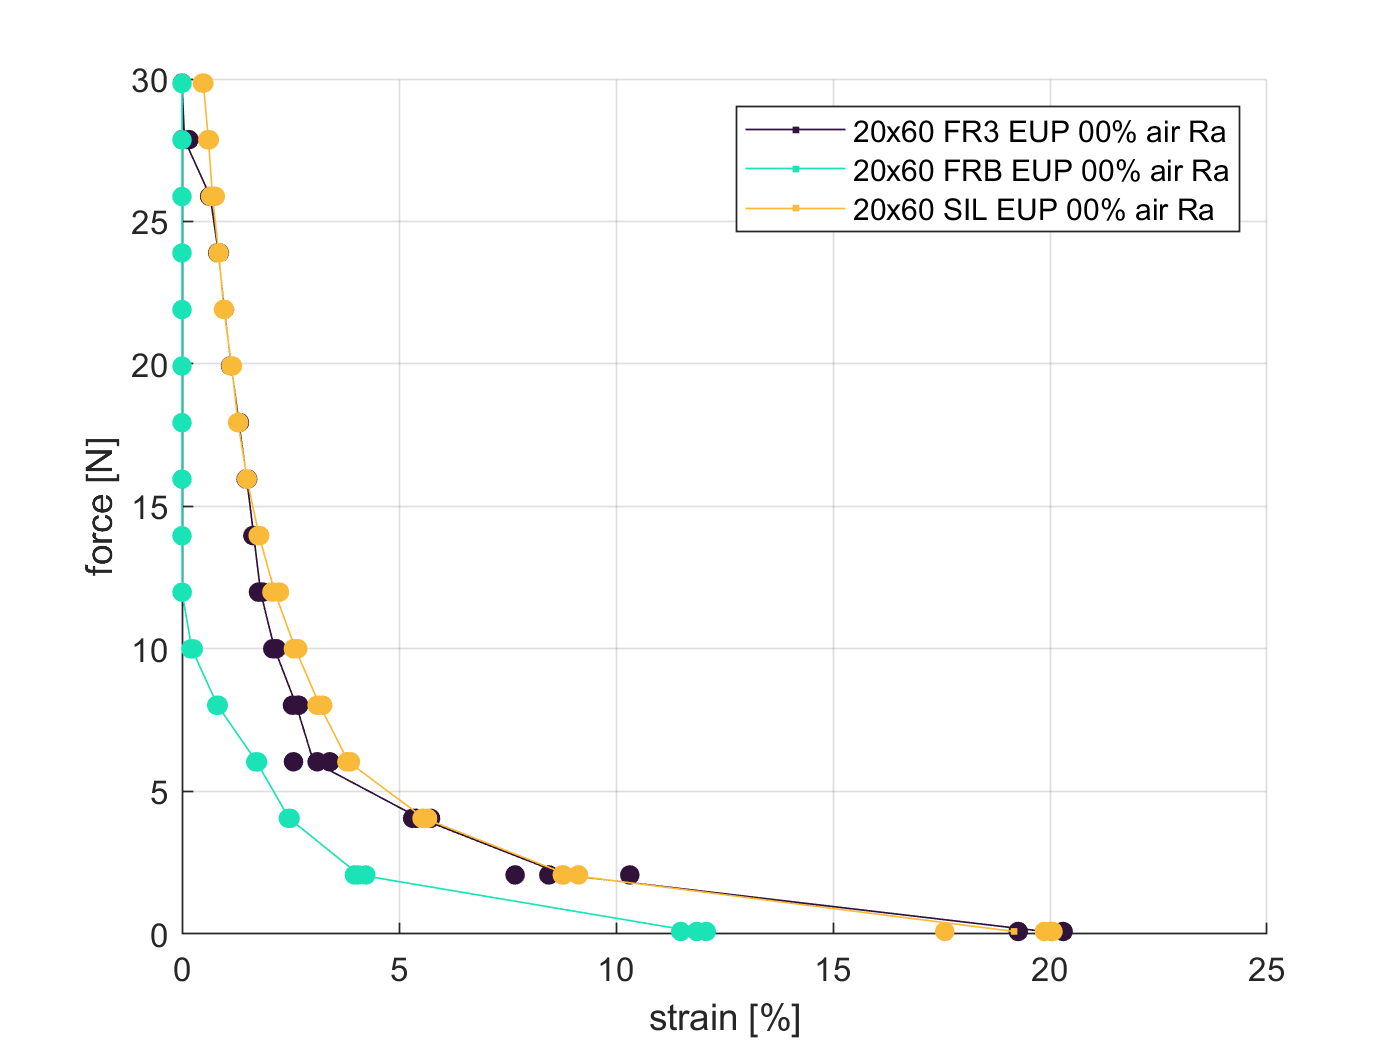

figure(2)
% figure("Visible","on")
clf
legendText = {length(FName), 1};

for i = 1: length(FName)
    fName = FName(i).name;
    %     if strcmp(fName, '20x60_EUP_SIL_85_05Hz_7kV_Stepinput.txt')
    %         h(i) = plot(0, 0, '.');
    %         legendText{i} = 'n/a';
    %         continue
    %     end
    
    %     [Time, Volt, Force, Disp, Trigger] = importfile_strainRaw(['raw_', fName]);
    %     [SF_strain, SF_force] = importfile_strain(fName);
    %     Volt = correctTimedelay(Volt);
    
    
    
    Colors = turbo(length(FName)+1);
    hold on
    if contains(fName, '10x60') % multiple strain if it's 10x60
        h(i) = plot([Data(i, :).strain]*2, [Data(i, :).force], '.-', 'Color', Colors(i, :));
        plot([Data(i, :).strain_raw]*2, repmat([Data(i, :).force], 3, 1), '.', "MarkerEdgeColor", Colors(i, :), 'MarkerSize', 20)
    else
        
        h(i) = plot([Data(i, :).strain]/20*100, [Data(i, :).force], '.-', 'Color', Colors(i, :));
        plot([Data(i, :).strain_raw]/20*100, repmat([Data(i, :).force], 3, 1), '.', "MarkerEdgeColor", Colors(i, :), 'MarkerSize', 20)
    end
    grid on
    xlabel('strain [%]')
    ylabel('force [N]')
    
    
    legendText{i} = [fName(1:5), ' ', fName(11:13), ' ', fName(7:9), ' ', fName(15:16), '% air ', fName(27:28)];
    
end

legend(h, legendText, "Interpreter", "none")

## plot bode with a new calculation

you can test other parameters for tfestimate


% figure(3)
% sampleRate = 2000;
% wind = hamming(sampleRate*2);
% [txy, ft] = tfestimate(refVolt, length, wind, [], [], sampleRate);
%
% subplot(2,1,1)
% hold on
% plot(ft, 10*log(abs(txy)))
% grid on
% xlim([0, 100])
%
% subplot(2,1,2)
% hold on
% plot(ft, unwrap(angle(txy))*180/pi)
% xlim([0, 100])
% grid on

function Out = correctTimedelay(Data)
Out = [Data(2:end); Data(end)];
end

function Out = detectStrain(Time, Force, Disp, targetForce, exPara, flagPlot)
samplesPerVolt = exPara.sampleFreq/exPara.inputFreq; % num samples per volt
samplesPerForceStep = samplesPerVolt * exPara.inputRepeat; % num samples per displacement step


i = targetForce/exPara.forceStep + 1;
startIndex = (i - 1)*samplesPerForceStep + 1;
endIndex = i*samplesPerForceStep;

Out.force = -mean(Force(startIndex: endIndex));

Ind_max = zeros(exPara.inputRepeat, 1);
Ind_min = zeros(exPara.inputRepeat, 1);
Val_max = zeros(exPara.inputRepeat, 1);
Val_min = zeros(exPara.inputRepeat, 1);

for j = 1: exPara.inputRepeat
    startIndex2 = startIndex + (j - 1)*samplesPerVolt;
    midIndex2 = startIndex2 + (1/2)*samplesPerVolt;
    endIndex2 = (startIndex - 1) + j*samplesPerVolt;
    [Val_max(j), Ind_max(j)] = max(Disp(startIndex2: midIndex2));
    [Val_min(j), Ind_min(j)] = min(Disp(midIndex2: endIndex2));
    
    Ind_max(j) = Ind_max(j) + startIndex2 - 1;
    Ind_min(j) = Ind_min(j) + midIndex2 - 1;
    
    if flagPlot
        yyaxis('right')
        plot(Time(Ind_min(j)), Disp(Ind_min(j)), 'bo', "LineWidth", 2)
        plot(Time(Ind_max(j)), Disp(Ind_max(j)), 'ro', 'LineWidth', 2)
    end
end
Out.strain_raw = Val_max - Val_min;
Out.strain = mean(Out.Strain_raw);

end


function out = detectStrain_cnv(Time, Force, Disp, targetForce, exPara, flagPlot)

spc= exPara.sampleFreq/exPara.inputFreq;
spf = spc * exPara.inputRepeat; % num samples per displacement step

i = targetForce/exPara.forceStep + 1;
startIndex = (i - 1)*spf + 1;
% endIndex = i*samplesPerForceStep;

max_stroke = zeros(exPara.inputRepeat, 1);
min_stroke = zeros(exPara.inputRepeat, 1);
rawStroke = zeros(exPara.inputRepeat, 1);
force = zeros(exPara.inputRepeat, 1);

rdr = exPara.rampTime*exPara.inputFreq; % ramp delay ratio in a cycle
hold = exPara.holdTime;

for j = 1: exPara.inputRepeat
    if i == 1
        ind_min_start = fix(startIndex + (hold - 0.01)*spc);
        ind_min_end = fix(startIndex + (hold + 0.00)*spc);
    else
        ind_min_start = fix(startIndex + (hold - 0.01)*spc +spc*(j-1));
        ind_min_end = fix(startIndex + (hold + 0.00)*spc +spc*(j-1));
    end
    ind_max_start = fix(startIndex + (hold + rdr + 0.01)*spc +spc*(j-1));
    ind_max_end = fix(startIndex + (hold + rdr + 0.02)*spc +spc*(j-1));
    
    max_stroke(j)=mean(Disp(ind_max_start: ind_max_end));
    min_stroke(j)=mean(Disp(ind_min_start: ind_min_end));
    force(j) = -mean(Force(ind_min_start: ind_min_end));
    
    rawStroke(j)= max([0, max_stroke(j) - min_stroke(j)]);
    
    if flagPlot
        yyaxis('right')
        plot([Time(ind_min_start), Time(ind_min_end)], [min_stroke(j), min_stroke(j)], 'bx-', "LineWidth", 2)
        plot([Time(ind_max_start), Time(ind_max_end)], [max_stroke(j), max_stroke(j)], 'rx-', "LineWidth", 2)
    end
end
out.strain_raw = rawStroke;
out.strain = mean(rawStroke);
% out.force = targetForce;
out.force = mean(force);


end
